# ***Energy conservation of the harmonic oscillator***

## `Describing the oscillators`

        The harmonic oscillator is one of the most important systems in physics because any object with mass subject to a force in stable equilibrium can act as one, both in nature and manmade devices, like radio and clocks. As such, being able to model any harmonic oscillator as accurately as possible will give us an incredibly useful tool.

        There are 3 main types of harmonic oscillators: **simple**, **damped** and **driven**. The simple oscillators are those where the movement is dictated by sinusoidal oscillations around the equilibrium point, having constant amplitude and frequency. When the oscillator becomes damped, then it is affected by friction that will slow down the object in time. In such cases, we get 3 subtypes: underdamped when the amplitude and frequency keep decreasing, overdamped when the object's amplitude decays to the equilibrium point without oscillating and critically damped when it doesn't oscillate but at the maximum velocity possible. Driven harmonic oscillators are damped ones that are also affected by an external force.

        Considering the most complex example, meaning the driven harmonic oscillator, calculating the displacement and velocity analytically can be challenging as the equation that needs to be solved is a differential one. Therefore, the easiest way to simulate such a model is by using a numerical method for integral computation. For this report, I've used MATLAB's `ode45` function, which implements the Runge-Kutta method of the 4th order. The only issue that arises from this is that the results may not be accurate, which is why we need to find the solution to the harmonic oscillator problem analytically.

clear variables;
clc;

m = 66.4; % mass
k = 3.3; % spring constant
c = 0; % viscous damping coefficient

x0 = 5.0; % initial displacement
v0 = 10.0; % initial velocity
f = @(t) 0; % forcing function

## `Solving the harmonic oscillator equation`

        The general equation of the harmonic oscillator is an inhomogeneous linear ordinary differential equation of the second-order. As such, we can employ the use of variation of parameters for the general second-order equations.


$$m\frac{{\mathrm{d}}^2 }{\mathrm{d}t^2 }q+c\frac{\mathrm{d}}{\mathrm{d}t}q+kq=f\Rightarrow \left\lbrace \begin{array}{l}
\frac{{\mathrm{d}}^2 }{\mathrm{d}t^2 }q+2\zeta \omega_0 \frac{\mathrm{d}}{\mathrm{d}t}q+\omega_0^2 q=\frac{1}{m}f\\
L=D^2 +2\zeta \omega_0 D+\omega_0^2 
\end{array}\Rightarrow Lq=\frac{1}{m}f\right.$$


        The next step is to solve the homogeneous version of the original equation, meaning that we'll be ignoring the driving force for the moment. Fortunately, the solutions to this problem are much easier to find.


$$\frac{{\mathrm{d}}^2 }{\mathrm{d}t^2 }q_T +2\zeta \omega_0 \frac{\mathrm{d}}{\mathrm{d}t}q_T +\omega_0^2 q_T =0$$



$$q_T =\left\lbrace \begin{array}{ll}
e^{-t\zeta \omega_0 } \left(C_1 e^{-t\omega_0 \sqrt{\zeta^2 -1}} +C_2 e^{t\omega_0 \sqrt{\zeta^2 -1}} \right) & \zeta >1\\
e^{-t\omega_0 } \left(C_1 t+C_2 \right) & \zeta =1\\
e^{-t\zeta \omega_0 } \left(C_1 \sin \left(t\omega_0 \sqrt{1-\zeta^2 }\right)+C_2 \cos \left(t\omega_0 \sqrt{1-\zeta^2 }\right)\right) & \zeta <1
\end{array}\right.$$


        We can split each solution in 2 parts as we know that they are still valid solutions to the homogeneous equation on top of being linearly independent of each other.


$$\left\lbrace \begin{array}{lll}
q_1 =C_1 e^{-t\omega_0 \left(\zeta +\sqrt{\zeta^2 -1}\right)}  & q_2 =C_2 e^{-t\omega_0 \left(\zeta -\sqrt{\zeta^2 -1}\right)}  & \zeta >1\\
q_1 =C_1 te^{-t\omega_0 }  & q_2 =C_2 e^{-t\omega_0 }  & \zeta =1\\
q_1 =C_1 \sin \left(t\omega_0 \sqrt{1-\zeta^2 }\right)e^{-t\zeta \omega_0 }  & q_2 =C_2 \cos \left(t\omega_0 \sqrt{1-\zeta^2 }\right)e^{-t\zeta \omega_0 }  & \zeta <1
\end{array}\right.$$



$$\frac{{\mathrm{d}}^2 }{\mathrm{d}t^2 }\left(q_1 +q_2 \right)+2\zeta \omega_0 \frac{\mathrm{d}}{\mathrm{d}t}\left(q_1 +q_2 \right)+\omega_0^2 \left(q_1 +q_2 \right)=0,\forall \zeta \ge 0$$


        Because the 2 parts are linearly independent, we now also know that the resulting Wronskian cannot be 0, which will be an important detail for later. At the moment, we can calculate it with the formula below.


$$W=W\left(q_1 ,q_2 \right)=q_1 \frac{\mathrm{d}}{\mathrm{d}t}q_2 -q_2 \frac{\mathrm{d}}{\mathrm{d}t}q_1 \Rightarrow W=\left\lbrace \begin{array}{ll}
2\omega_0 C_1 C_2 e^{-2t\zeta \omega_0 } \sqrt{\zeta^2 -1} & \zeta >1\\
-C_1 C_2 e^{-2t\omega_0 }  & \zeta =1\\
-\omega_0 C_1 C_2 e^{-2t\zeta \omega_0 } \sqrt{1-\zeta^2 } & \zeta <1
\end{array}\Rightarrow W\not= 0,\forall C_1 \not= 0,C_2 \not= 0,\zeta \ge 0\right.$$


        Now that we found the solution to the homogeneous equation, we'll have to find a particular solution to the original equation.


$$\left\lbrace \begin{array}{l}
{Aq}_1 +{Bq}_2 =q_P \\
q_1 \frac{\mathrm{d}}{\mathrm{d}t}A+q_2 \frac{\mathrm{d}}{\mathrm{d}t}B=0
\end{array}\right.$$


        By "particular" we mean that there could be infinitely many solutions but all we need is just one of them. This is why the system above has another equation below: we need at least 2 equations in order to find a specific solution for the 2 unknown variables, otherwise we wouldn't be able to find a particular solution.


$$\frac{\mathrm{d}}{\mathrm{d}t}q_P =\frac{\mathrm{d}}{\mathrm{d}t}\left({Aq}_1 +{Bq}_2 \right)=\frac{\mathrm{d}}{\mathrm{d}t}{Aq}_1 +\frac{\mathrm{d}}{\mathrm{d}t}{Bq}_2 =q_1 \frac{\mathrm{d}}{\mathrm{d}t}A+A\frac{\mathrm{d}}{\mathrm{d}t}q_1 +q_2 \frac{\mathrm{d}}{\mathrm{d}t}B+B\frac{\mathrm{d}}{\mathrm{d}t}q_2 =A\frac{\mathrm{d}}{\mathrm{d}t}q_1 +B\frac{\mathrm{d}}{\mathrm{d}t}q_2$$


        Differentiating twice, we can learn more about the relationship between the unknown variables and the particular solution.


$$\frac{{\mathrm{d}}^2 }{\mathrm{d}t^2 }q_P =A\frac{{\mathrm{d}}^2 }{\mathrm{d}t^2 }q_1 +\frac{\mathrm{d}}{\mathrm{d}t}A\frac{\mathrm{d}}{\mathrm{d}t}q_1 +B\frac{{\mathrm{d}}^2 }{\mathrm{d}t^2 }q_2 +\frac{\mathrm{d}}{\mathrm{d}t}B\frac{\mathrm{d}}{\mathrm{d}t}q_2$$



$${Lq}_P ={ALq}_1 +{BLq}_2 +\frac{\mathrm{d}}{\mathrm{d}t}A\frac{\mathrm{d}}{\mathrm{d}t}q_1 +\frac{\mathrm{d}}{\mathrm{d}t}B\frac{\mathrm{d}}{\mathrm{d}t}q_2 \Leftrightarrow {Lq}_P =\frac{\mathrm{d}}{\mathrm{d}t}A\frac{\mathrm{d}}{\mathrm{d}t}q_1 +\frac{\mathrm{d}}{\mathrm{d}t}B\frac{\mathrm{d}}{\mathrm{d}t}q_2$$


        The above information can be rewritten in matrix form for better visualisation. After that, we can solve for the derivatives of the unknown variables, which we can then integrate to complete the system.


$$\left\lbrack \begin{array}{cc}
q_1  & q_2 \\
\frac{\mathrm{d}}{\mathrm{d}t}q_1  & \frac{\mathrm{d}}{\mathrm{d}t}q_2 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\frac{\mathrm{d}}{\mathrm{d}t}A\\
\frac{\mathrm{d}}{\mathrm{d}t}B
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
\frac{1}{m}f
\end{array}\right\rbrack \Leftrightarrow \left\lbrack \begin{array}{c}
q_1 \frac{\mathrm{d}}{\mathrm{d}t}A+q_2 \frac{\mathrm{d}}{\mathrm{d}t}B\\
\frac{\mathrm{d}}{\mathrm{d}t}A\frac{\mathrm{d}}{\mathrm{d}t}q_1 +\frac{\mathrm{d}}{\mathrm{d}t}B\frac{\mathrm{d}}{\mathrm{d}t}q_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
\frac{1}{m}f
\end{array}\right\rbrack \Leftrightarrow \left\lbrace \begin{array}{l}
q_1 \frac{\mathrm{d}}{\mathrm{d}t}A+q_2 \frac{\mathrm{d}}{\mathrm{d}t}B=0\\
\frac{\mathrm{d}}{\mathrm{d}t}A\frac{\mathrm{d}}{\mathrm{d}t}q_1 +\frac{\mathrm{d}}{\mathrm{d}t}B\frac{\mathrm{d}}{\mathrm{d}t}q_2 ={\textrm{Lq}}_P =\frac{1}{m}f
\end{array}\right.$$



$$\left\lbrack \begin{array}{cc}
q_1  & q_2 \\
\frac{\mathrm{d}}{\mathrm{d}t}q_1  & \frac{\mathrm{d}}{\mathrm{d}t}q_2 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\frac{\mathrm{d}}{\mathrm{d}t}A\\
\frac{\mathrm{d}}{\mathrm{d}t}B
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
\frac{1}{m}f
\end{array}\right\rbrack \Leftrightarrow \left\lbrack \begin{array}{c}
\frac{\mathrm{d}}{\mathrm{d}t}A\\
\frac{\mathrm{d}}{\mathrm{d}t}B
\end{array}\right\rbrack ={\left\lbrack \begin{array}{cc}
q_1  & q_2 \\
\frac{\mathrm{d}}{\mathrm{d}t}q_1  & \frac{\mathrm{d}}{\mathrm{d}t}q_2 
\end{array}\right\rbrack }^{-1} \left\lbrack \begin{array}{c}
0\\
\frac{1}{m}f
\end{array}\right\rbrack =\frac{1}{W}\left\lbrack \begin{array}{cc}
\frac{\mathrm{d}}{\mathrm{d}t}q_2  & -q_2 \\
-\frac{\mathrm{d}}{\mathrm{d}t}q_1  & q_1 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
0\\
\frac{1}{m}f
\end{array}\right\rbrack$$



$$\left\lbrace \begin{array}{l}
\frac{\mathrm{d}}{\mathrm{d}t}A=-\frac{1}{m}f\frac{q_2 }{W}\\
\frac{\mathrm{d}}{\mathrm{d}t}B=\frac{1}{m}f\frac{q_1 }{W}
\end{array}\Leftrightarrow \left\lbrace \begin{array}{l}
A=-\frac{1}{m}\int f\frac{q_2 }{W}\textrm{dt}\\
B=\frac{1}{m}\int f\frac{q_1 }{W}\textrm{dt}
\end{array}\right.\right.$$



$$\left\lbrace \begin{array}{lll}
A=-\frac{1}{2m\omega_0 C_1 \sqrt{\zeta^2 -1}}\int fe^{t\omega_0 \left(\zeta +\sqrt{\zeta^2 -1}\right)} \mathrm{dt} & B=\frac{1}{2m\omega_0 C_2 \sqrt{\zeta^2 -1}}\int fe^{t\omega_0 \left(\zeta -\sqrt{\zeta^2 -1}\right)} \mathrm{dt} & \zeta >1\\
A=\frac{1}{mC_1 }\int fe^{t\omega_0 } \mathrm{dt} & B=-\frac{1}{mC_2 }\int f\;te^{t\omega_0 } \mathrm{dt} & \zeta =1\\
A=\frac{1}{m\omega_0 C_1 \sqrt{1-\zeta^2 }}\int fe^{t\zeta \omega_0 } \cos \left(t\omega_0 \sqrt{1-\zeta^2 }\right)\mathrm{dt} & B=-\frac{1}{m\omega_0 C_2 \sqrt{1-\zeta^2 }}\int fe^{t\zeta \omega_0 } \sin \left(t\omega_0 \sqrt{1-\zeta^2 }\right)\mathrm{dt} & \zeta <1
\end{array}\right.$$


        Because the integrals above depend on the driving force, we cannot solve them without knowing the exact force applied. As such, we'll give them names to keep track of them.


$$\left\lbrace \begin{array}{lll}
f_1 =f\frac{e^{t\omega_0 \left(\zeta +\sqrt{\zeta^2 -1}\right)} }{m} & f_2 =f\frac{e^{t\omega_0 \left(\zeta -\sqrt{\zeta^2 -1}\right)} }{m} & \zeta >1\\
f_1 =f\frac{e^{t\omega_0 } }{m} & f_2 =f\frac{te^{t\omega_0 } }{m}\; & \zeta =1\\
f_1 =f\frac{e^{t\zeta \omega_0 } \cos \left(t\omega_0 \sqrt{1-\zeta^2 }\right)}{m} & f_2 =f\frac{e^{t\zeta \omega_0 } \sin \left(t\omega_0 \sqrt{1-\zeta^2 }\right)}{m} & \zeta <1
\end{array}\Rightarrow \left\lbrace \begin{array}{lll}
F_1 =\int f_1 \mathrm{dt} & F_2 =\int f_2 \mathrm{dt} & \zeta >1\\
F_1 =\int f_1 \mathrm{dt} & F_2 =\int f_2 \mathrm{dt} & \zeta =1\\
F_1 =\int f_1 \mathrm{dt} & F_2 =\int f_2 \mathrm{dt} & \zeta <1
\end{array}\right.\right.$$


        In the end, we have found a particular solution to the inhomogenous equation, which we can then add with the homogeneous solution to get the general solution


$$q_P =\left\lbrace \begin{array}{ll}
\frac{e^{-t\zeta \omega_0 } }{2\omega_0 \sqrt{\zeta^2 -1}}\left(e^{t\omega_0 \sqrt{\zeta^2 -1}} F_2 -e^{-t\omega_0 \sqrt{\zeta^2 -1}} F_1 \right) & \zeta >1\\
e^{-t\omega_0 } \left(tF_1 -F_2 \right) & \zeta =1\\
\frac{e^{-t\zeta \omega_0 } }{\omega_0 \sqrt{1-\zeta^2 }}\left(\sin \left(t\omega_0 \sqrt{1-\zeta^2 }\right)F_1 -\cos \left(t\omega_0 \sqrt{1-\zeta^2 }\right)F_2 \right) & \zeta <1
\end{array}\right.$$



$$q=\left\lbrace \begin{array}{ll}
\frac{e^{-t\zeta \omega_0 } }{2\omega_0 \sqrt{\zeta^2 -1}}\left(e^{t\omega_0 \sqrt{\zeta^2 -1}} \left(C_2 +F_2 \right)-e^{-t\omega_0 \sqrt{\zeta^2 -1}} \left(C_1 +F_1 \right)\right) & \zeta >1\\
e^{-t\omega_0 } \left(t\left(C_1 +F_1 \right)-\left(C_2 +F_2 \right)\right) & \zeta =1\\
\frac{e^{-t\zeta \omega_0 } }{\omega_0 \sqrt{1-\zeta^2 }}\left(\sin \left(t\omega_0 \sqrt{1-\zeta^2 }\right)\left(C_1 +F_1 \right)-\cos \left(t\omega_0 \sqrt{1-\zeta^2 }\right)\left(C_2 +F_2 \right)\right) & \zeta <1
\end{array}\right.$$



$$\frac{{\mathrm{d}}^2 }{\mathrm{d}t^2 }\left(q_T +q_P \right)+2\zeta \omega_0 \frac{\mathrm{d}}{\mathrm{d}t}\left(q_T +q_P \right)+\omega_0^2 \left(q_T +q_P \right)=\frac{1}{m}f,\forall \;\zeta \ge 0$$


        The constants of integration will depend on the initial conditions of the system, which is how we can learn the exact values by solving an easy equation at the very start of the simulation.


$$x_0 =q\left(0\right)\Leftrightarrow x_0 =\left\lbrace \begin{array}{ll}
\frac{C_2 +F_2 \left(0\right)-C_1 -F_1 \left(0\right)}{2\omega_0 \sqrt{\zeta^2 -1}} & \zeta >1\\
-C_2 -F_2 \left(0\right) & \zeta =1\\
-\frac{C_2 +F_2 \left(0\right)}{\omega_0 \sqrt{1-\zeta^2 }} & \zeta <1
\end{array}\Leftrightarrow C_2 =\left\lbrace \begin{array}{ll}
2x_0 \omega_0 \sqrt{\zeta^2 -1}+C_1 +F_1 \left(0\right)-F_2 \left(0\right) & \zeta >1\\
-x_0 -F_2 \left(0\right) & \zeta =1\\
-x_0 \omega_0 \sqrt{1-\zeta^2 }-F_2 \left(0\right) & \zeta <1
\end{array}\right.\right.$$


        Replacing the above constant with the computed values will result in a longer displacement equation.


$$q=\left\lbrace \begin{array}{ll}
\frac{1}{2\omega_0 \sqrt{\zeta^2 -1}}\left(e^{-t\omega_0 \left(\zeta -\sqrt{\zeta^2 -1}\right)} \left(2x_0 \omega_0 \sqrt{\zeta^2 -1}+C_1 +F_1 \left(0\right)-F_2 \left(0\right)+F_2 \right)-e^{-t\omega_0 \left(\zeta +\sqrt{\zeta^2 -1}\right)} \left(C_1 +F_1 \right)\right) & \zeta >1\\
te^{-t\omega_0 } \left(C_1 +F_1 \right)+e^{-t\omega_0 } \left(x_0 +F_2 \left(0\right)-F_2 \right) & \zeta =1\\
\frac{1}{\omega_0 \sqrt{1-\zeta^2 }}\left(e^{-t\zeta \omega_0 } \sin \left(t\omega_0 \sqrt{1-\zeta^2 }\right)\left(C_1 +F_1 \right)+e^{-t\zeta \omega_0 } \cos \left(t\omega_0 \sqrt{1-\zeta^2 }\right)\left(x_0 \omega_0 \sqrt{1-\zeta^2 }+F_2 \left(0\right)-F_2 \right)\right) & \zeta <1
\end{array}\right.$$


        To finish things off, we need to do the same thing for the other initial value, the one for velocity. In order to do that, we'll have to differentiate the above equation and solve for the last constant of integration.


$$\frac{\mathrm{d}}{\mathrm{d}t}q=X+Y,\left\lbrace \begin{array}{ll}
\left\lbrace \begin{array}{l}
X=\frac{e^{-t\omega_0 \left(\zeta -\sqrt{\zeta^2 -1}\right)} }{2\omega_0 \sqrt{\zeta^2 -1}}\left(\omega_0 \left(\sqrt{\zeta^2 -1}-\zeta \right)\left(2x_0 \omega_0 \sqrt{\zeta^2 -1}+C_1 +F_1 \left(0\right)-F_2 \left(0\right)+F_2 \right)+\frac{d}{\mathrm{d}t}F_2 \right)\\
Y=\frac{e^{-t\omega_0 \left(\zeta +\sqrt{\zeta^2 -1}\right)} }{2\omega_0 \sqrt{\zeta^2 -1}}\left(\omega_0 \left(\sqrt{\zeta^2 -1}+\zeta \right)\left(C_1 +F_1 \right)-\frac{d}{\mathrm{d}t}F_1 \right)
\end{array}\right. & \zeta >1\\
\left\lbrace \begin{array}{l}
X=e^{-t\omega_0 } \left(C_1 +F_1 -\omega_0 \left(x_0 +F_2 \left(0\right)-F_2 \right)-\frac{d}{\mathrm{d}t}F_2 \right)\\
Y=-te^{-t\omega_0 } \left(\omega_0 \left(C_1 +F_1 \right)-\frac{d}{\mathrm{d}t}F_1 \right)
\end{array}\right. & \zeta =1\\
\left\lbrace \begin{array}{l}
X=\frac{e^{-t\zeta \omega_0 } \cos \left(t\omega_0 \sqrt{1-\zeta^2 }\right)}{\omega_0 \sqrt{1-\zeta^2 }}\left(\omega_0 \left(\sqrt{1-\zeta^2 }\left(C_1 +F_1 \right)-\zeta \left(x_0 \omega_0 \sqrt{1-\zeta^2 }+F_2 \left(0\right)-F_2 \right)\right)-\frac{d}{\mathrm{d}t}F_2 \right)\\
Y=-\frac{e^{-t\zeta \omega_0 } \sin \left(t\omega_0 \sqrt{1-\zeta^2 }\right)}{\omega_0 \sqrt{1-\zeta^2 }}\left(\omega_0 \left(\sqrt{1-\zeta^2 }\left(x_0 \omega_0 \sqrt{1-\zeta^2 }+F_2 \left(0\right)-F_2 \right)+\zeta \left(C_1 +F_1 \right)\right)-\frac{d}{\mathrm{d}t}F_1 \right)
\end{array}\right. & \zeta <1
\end{array}\right.$$



$$v_0 =\frac{\mathrm{d}}{\mathrm{d}t}q\left(0\right)\Leftrightarrow v_0 =\left\lbrace \begin{array}{ll}
C_1 +x_0 \omega_0 \left(\sqrt{\zeta^2 -1}-\zeta \right)+F_1 \left(0\right) & \zeta >1\\
C_1 -x_0 \omega_0 +F_1 \left(0\right) & \zeta =1\\
C_1 -\zeta x_0 +F_1 \left(0\right) & \zeta <1
\end{array}\Leftrightarrow C_1 =\left\lbrace \begin{array}{ll}
v_0 -x_0 \omega_0 \left(\sqrt{\zeta^2 -1}-\zeta \right)-F_1 \left(0\right) & \zeta >1\\
v_0 +x_0 \omega_0 -F_1 \left(0\right) & \zeta =1\\
v_0 +\zeta x_0 -F_1 \left(0\right) & \zeta <1
\end{array}\right.\right.$$



$$C_2 =\left\lbrace \begin{array}{ll}
2x_0 \omega_0 \sqrt{\zeta^2 -1}+C_1 +F_1 \left(0\right)-F_2 \left(0\right) & \zeta >1\\
-x_0 -F_2 \left(0\right) & \zeta =1\\
-x_0 \omega_0 \sqrt{1-\zeta^2 }-F_2 \left(0\right) & \zeta <1
\end{array}\Leftrightarrow C_2 =\left\lbrace \begin{array}{ll}
v_0 +x_0 \omega_0 \left(\sqrt{\zeta^2 -1}+\zeta \right)-F_2 \left(0\right) & \zeta >1\\
-x_0 -F_2 \left(0\right) & \zeta =1\\
-x_0 \omega_0 \sqrt{1-\zeta^2 }-F_2 \left(0\right) & \zeta <1
\end{array}\right.\right.$$


        Finally, we get the complete analytical solutions for the displacement and velocity of any given harmonic oscillator.


$$\frac{\mathrm{d}}{\mathrm{d}t}q=X+Y,\left\lbrace \begin{array}{ll}
\left\lbrace \begin{array}{l}
X=\frac{e^{-t\omega_0 \left(\zeta -\sqrt{\zeta^2 -1}\right)} }{2\omega_0 \sqrt{\zeta^2 -1}}\left(\omega_0 \left(\sqrt{\zeta^2 -1}-\zeta \right)\left(v_0 +x_0 \omega_0 \left(\sqrt{\zeta^2 -1}+\zeta \right)-F_2 \left(0\right)+F_2 \right)+\frac{d}{\mathrm{d}t}F_2 \right)\\
Y=\frac{e^{-t\omega_0 \left(\zeta +\sqrt{\zeta^2 -1}\right)} }{2\omega_0 \sqrt{\zeta^2 -1}}\left(\omega_0 \left(\sqrt{\zeta^2 -1}+\zeta \right)\left(v_0 -x_0 \omega_0 \left(\sqrt{\zeta^2 -1}-\zeta \right)-F_1 \left(0\right)+F_1 \right)-\frac{d}{\mathrm{d}t}F_1 \right)
\end{array}\right. & \zeta >1\\
\left\lbrace \begin{array}{l}
X=e^{-t\omega_0 } \left(v_0 -F_1 \left(0\right)+F_1 -\omega_0 \left(F_2 \left(0\right)-F_2 \right)-\frac{d}{\mathrm{d}t}F_2 \right)\\
Y=-te^{-t\omega_0 } \left(\omega_0 \left(v_0 +x_0 \omega_0 -F_1 \left(0\right)+F_1 \right)-\frac{d}{\mathrm{d}t}F_1 \right)
\end{array}\right. & \zeta =1\\
\left\lbrace \begin{array}{l}
X=\frac{\cos \left(t\omega_0 \sqrt{1-\zeta^2 }\right)}{e^{t\zeta \omega_0 } \omega_0 \sqrt{1-\zeta^2 }}\left(\omega_0 \left(\sqrt{1-\zeta^2 }\left(v_0 +\zeta x_0 -F_1 \left(0\right)+F_1 \right)-\zeta \left(x_0 \omega_0 \sqrt{1-\zeta^2 }+F_2 \left(0\right)-F_2 \right)\right)-\frac{d}{\mathrm{d}t}F_2 \right)\\
Y=-\frac{\sin \left(t\omega_0 \sqrt{1-\zeta^2 }\right)}{e^{t\zeta \omega_0 } \omega_0 \sqrt{1-\zeta^2 }}\left(\omega_0 \left(\sqrt{1-\zeta^2 }\left(x_0 \omega_0 \sqrt{1-\zeta^2 }+F_2 \left(0\right)-F_2 \right)+\zeta \left(v_0 +\zeta x_0 -F_1 \left(0\right)+F_1 \right)\right)-\frac{d}{\mathrm{d}t}F_1 \right)
\end{array}\right. & \zeta <1
\end{array}\right.$$



$$q=\left\lbrace \begin{array}{ll}
\frac{e^{-t\zeta \omega_0 } }{2\omega_0 \sqrt{\zeta^2 -1}}\left(e^{t\omega_0 \sqrt{\zeta^2 -1}} \left(v_0 +x_0 \omega_0 \left(\sqrt{\zeta^2 -1}+\zeta \right)-F_2 \left(0\right)+F_2 \right)-e^{-t\omega_0 \sqrt{\zeta^2 -1}} \left(v_0 -x_0 \omega_0 \left(\sqrt{\zeta^2 -1}-\zeta \right)-F_1 \left(0\right)+F_1 \right)\right) & \zeta >1\\
e^{-t\omega_0 } \left(t\left(v_0 +x_0 \omega_0 -F_1 \left(0\right)+F_1 \right)+x_0 +F_2 \left(0\right)-F_2 \right) & \zeta =1\\
\frac{e^{-t\zeta \omega_0 } }{\omega_0 \sqrt{1-\zeta^2 }}\left(\sin \left(t\omega_0 \sqrt{1-\zeta^2 }\right)\left(v_0 +\zeta x_0 -F_1 \left(0\right)+F_1 \right)+\cos \left(t\omega_0 \sqrt{1-\zeta^2 }\right)\left(x_0 \omega_0 \sqrt{1-\zeta^2 }+F_2 \left(0\right)-F_2 \right)\right) & \zeta <1
\end{array}\right.$$


## `Comparing the results`

        Now that we know how to compute the displacement and velocity of a given harmonic oscillator, we can plot the results to compare the methods. Additionally, we can calculate the total energy of the system by adding the kinetic and potential energies together and then plot those. Below is an example of a simple harmonic with the values defined at the beginning of this report.

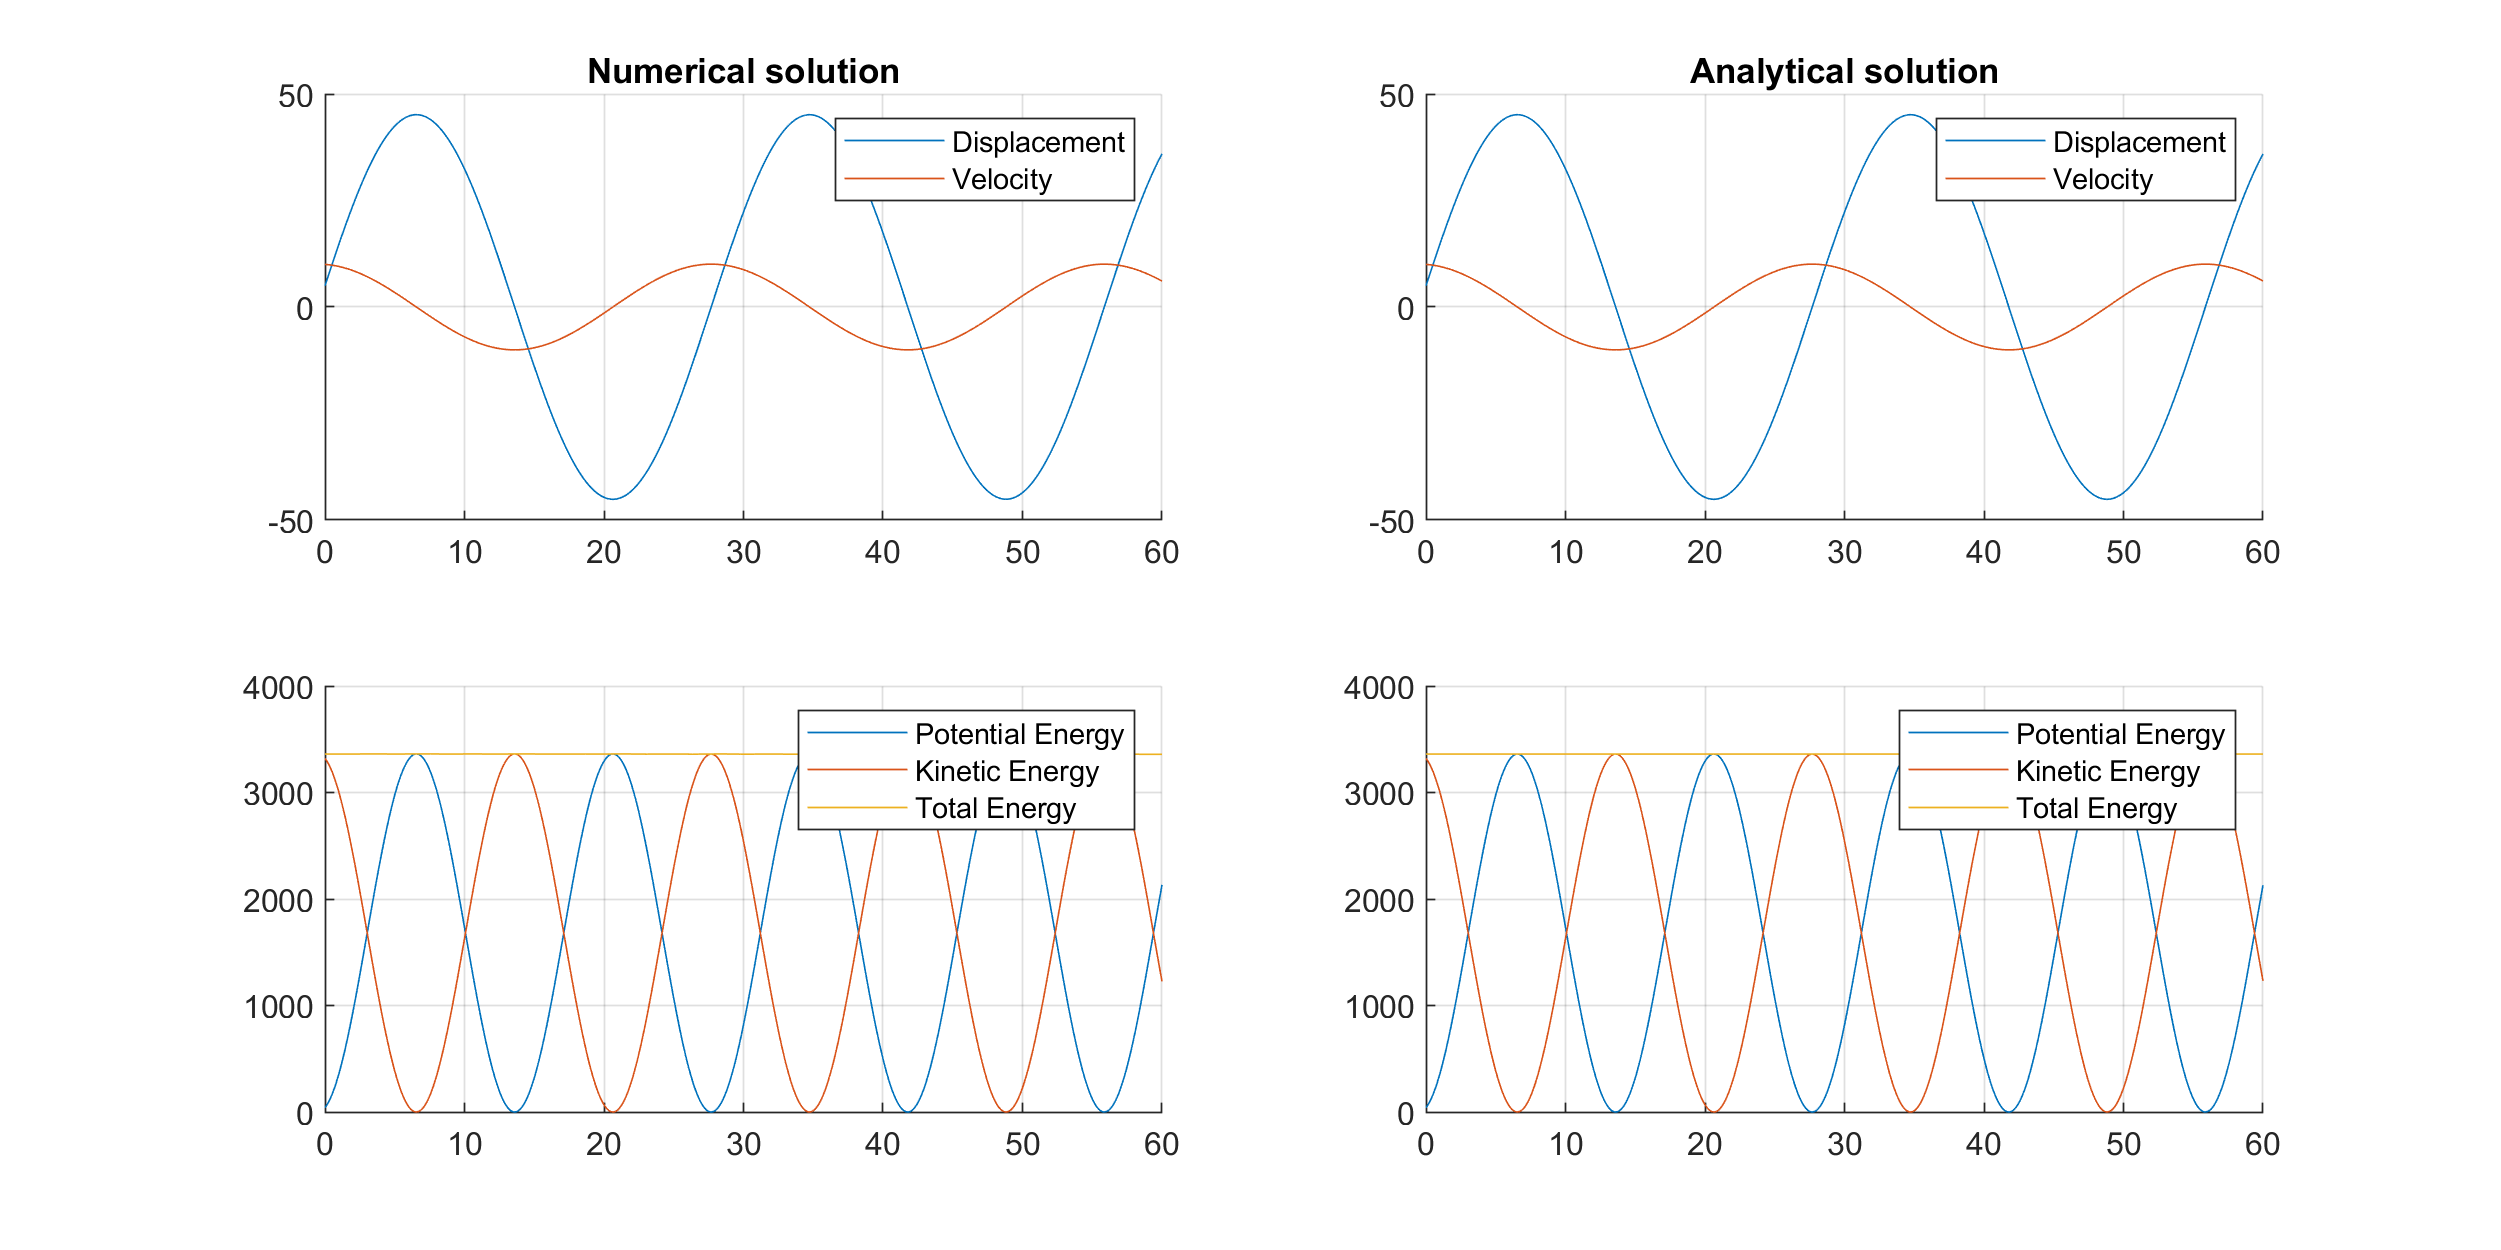

Elapsed time is 2.107156 seconds.


time = linspace(0.0, 60.0, 1000);
compare_q(m, k, c, x0, v0, f, time);

        As we can see, the graphs are essentially identical, which is a good thing because it leads us to believe that our analytical equation is correct and that the numerical variant is a much more efficient method of getting the same output. Let's test the exact same system but over a longer timespan to see if our assumptions hold true.

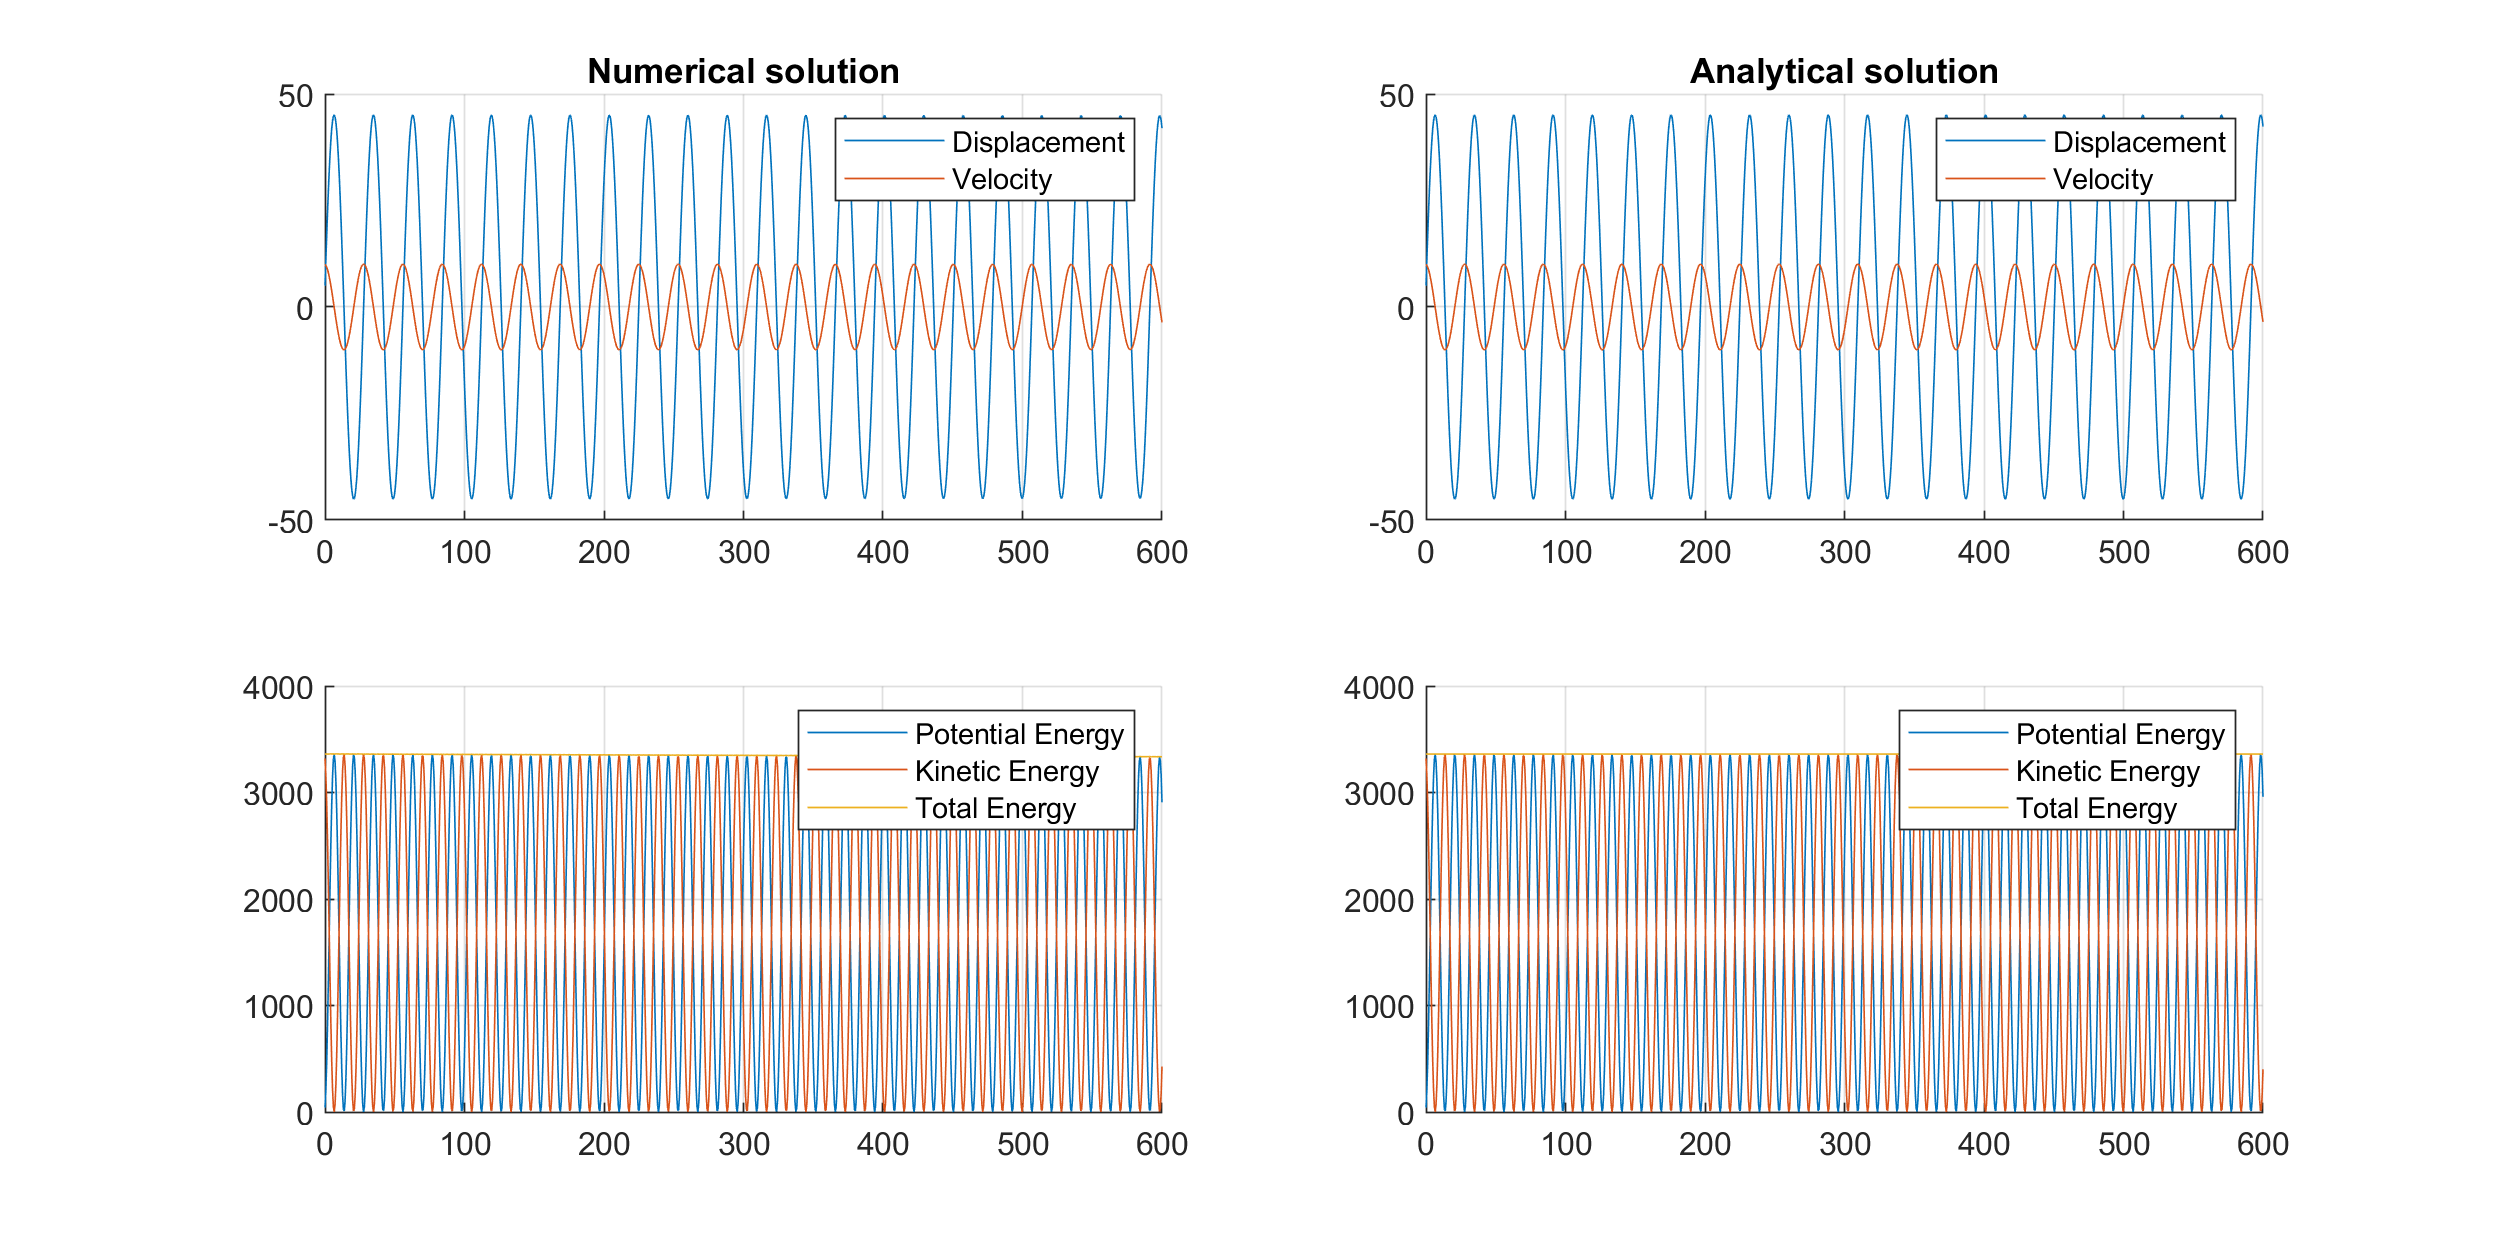

Elapsed time is 1.995092 seconds.


time = linspace(0.0, 600.0, 1000);
compare_q(m, k, c, x0, v0, f, time);

        Curiously, the plots still look the same, which is further confirmation to what we're looking for. However, the illusion shatters once we try again for an even longer time period.

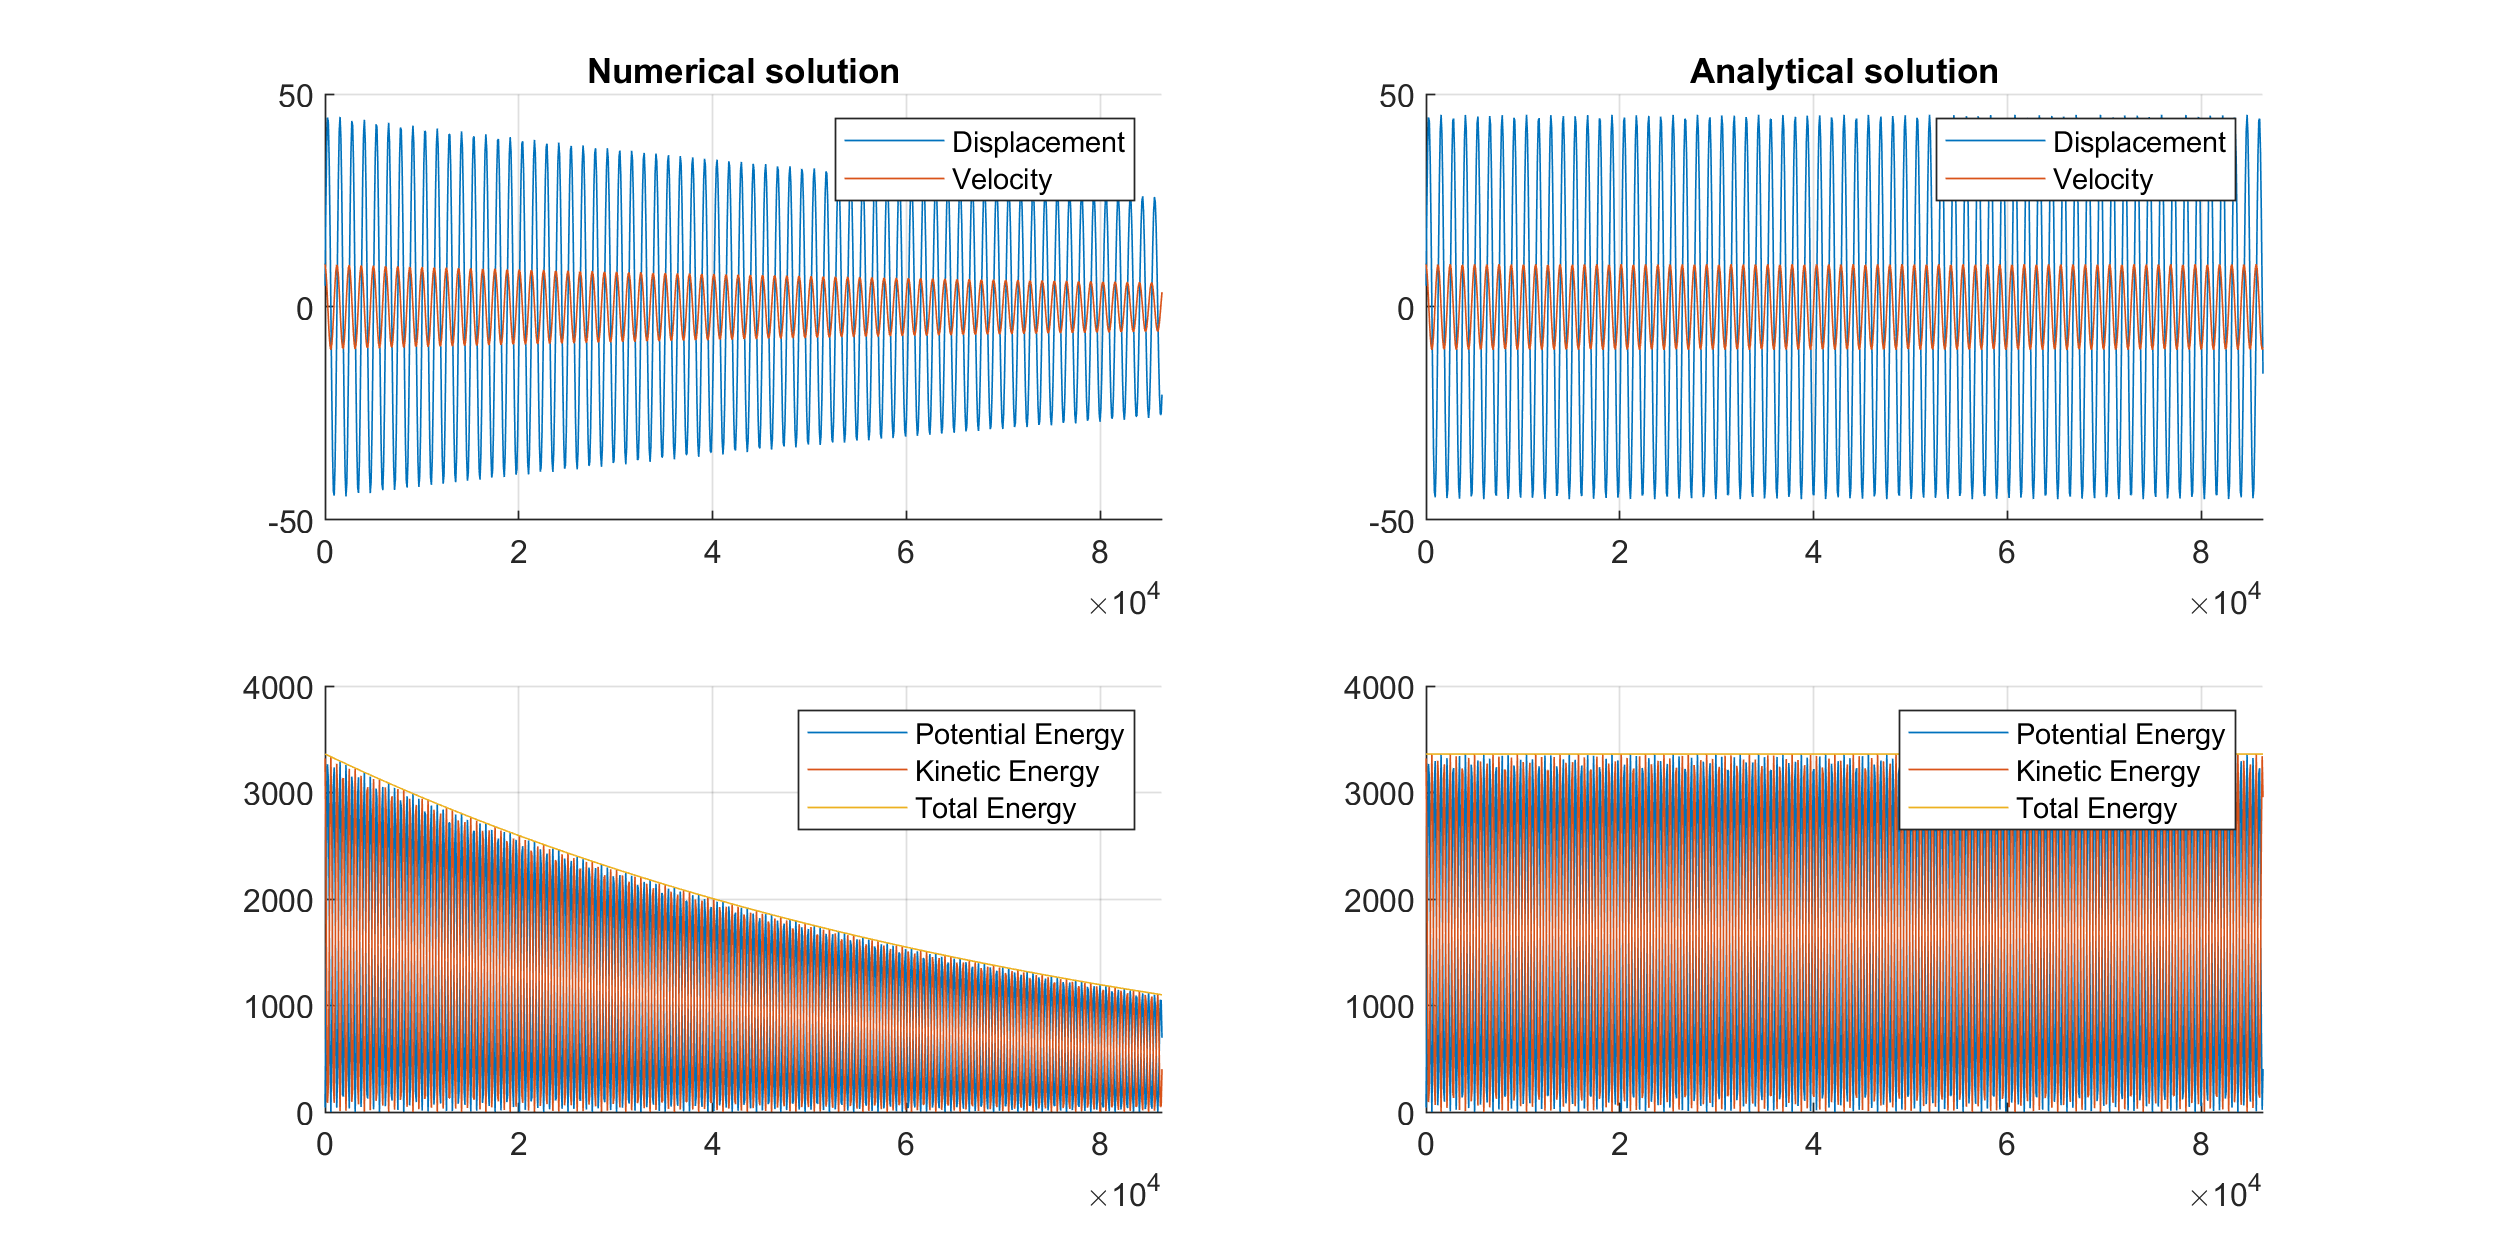

Elapsed time is 2.355615 seconds.


time = linspace(0.0, 86400.0, 1000);
compare_q(m, k, c, x0, v0, f, time);

        The graphs above tell the whole story: the numerical and analytical solutions are, in fact, not identical when considering longer periods of time. In this case, the timeframe can be interpreted as 24 hours. The differences are obvious in such a case: the numerical solution loses energy continuously, despite the fact that this harmonic oscillator is simple, so there is no damping involved. Because of this, we can conclude that the analytical method is correct since the total energy is constant.

        This phenomenon is called energy drift and it happens because the numerical method is unable to compute the exact values; it can only approximate the result at a given time. These numerical errors are incredibly small, but they will add up without stopping, which is the reason for energy loss over longer periods of time. This, unfortunately, is an inevitability of trying to solve an equation numerically. Trying to compute problems that can't be solved analytically will always lead to such outcomes with no real way of mitigating the issue other than using another method.

        With all that said, let's see what happens when damping occurs in all 3 cases. By definition, we should notice the total energy steadily decreasing.

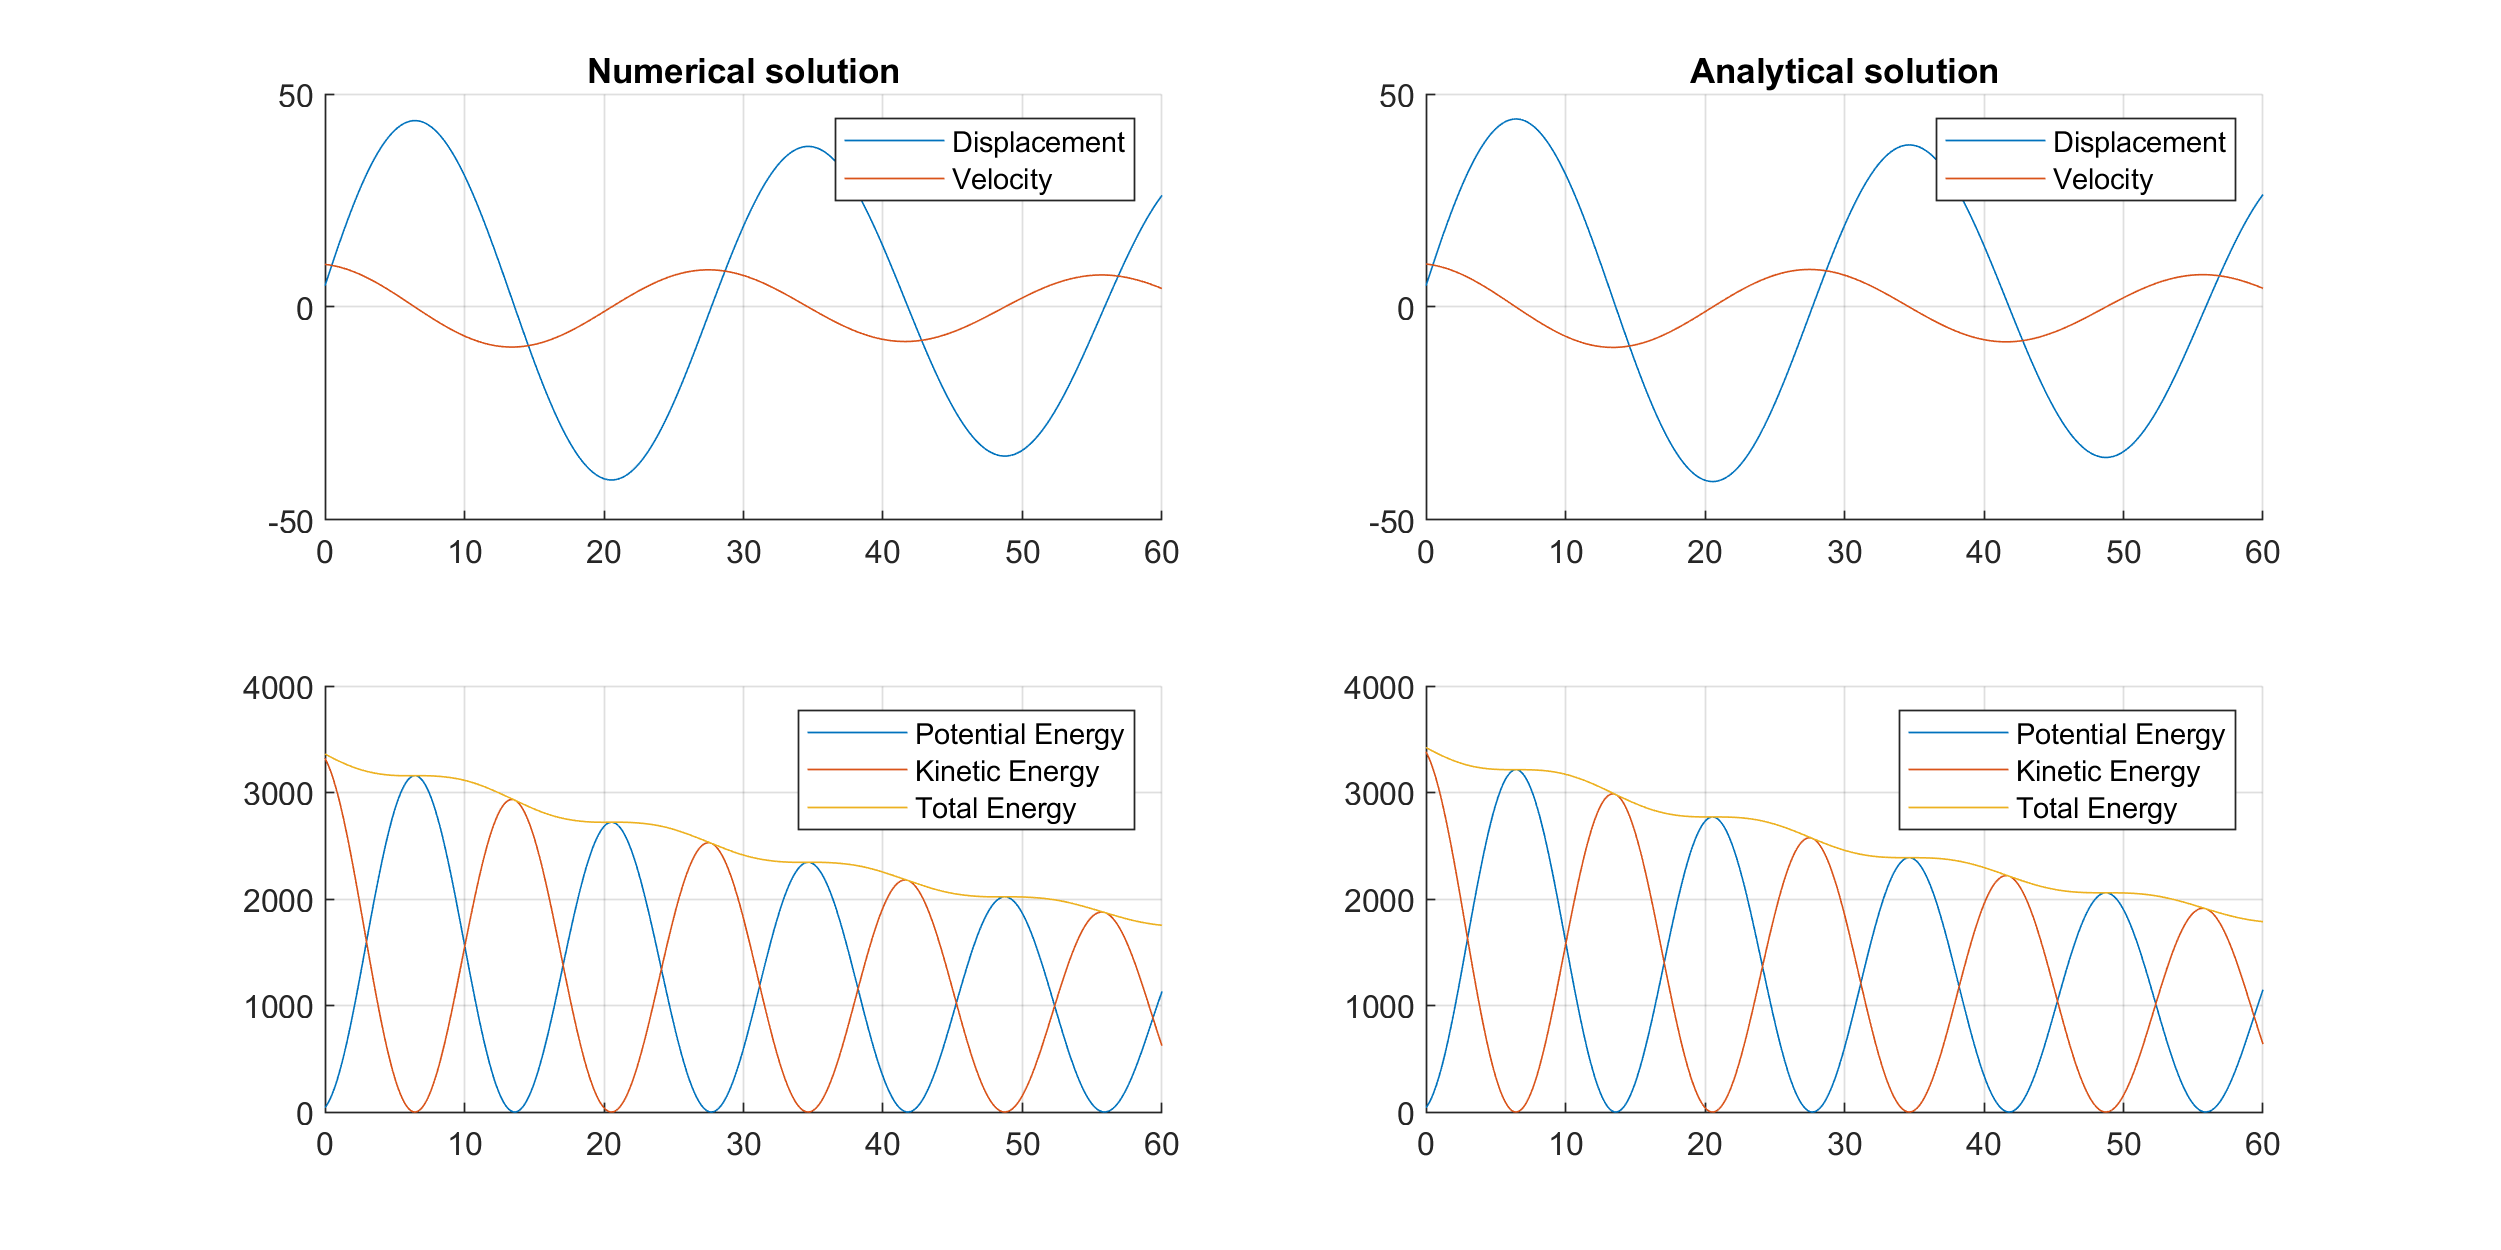

Elapsed time is 2.488972 seconds.


c = 0.7;
time = linspace(0.0, 60.0, 1000);
compare_q(m, k, c, x0, v0, f, time);

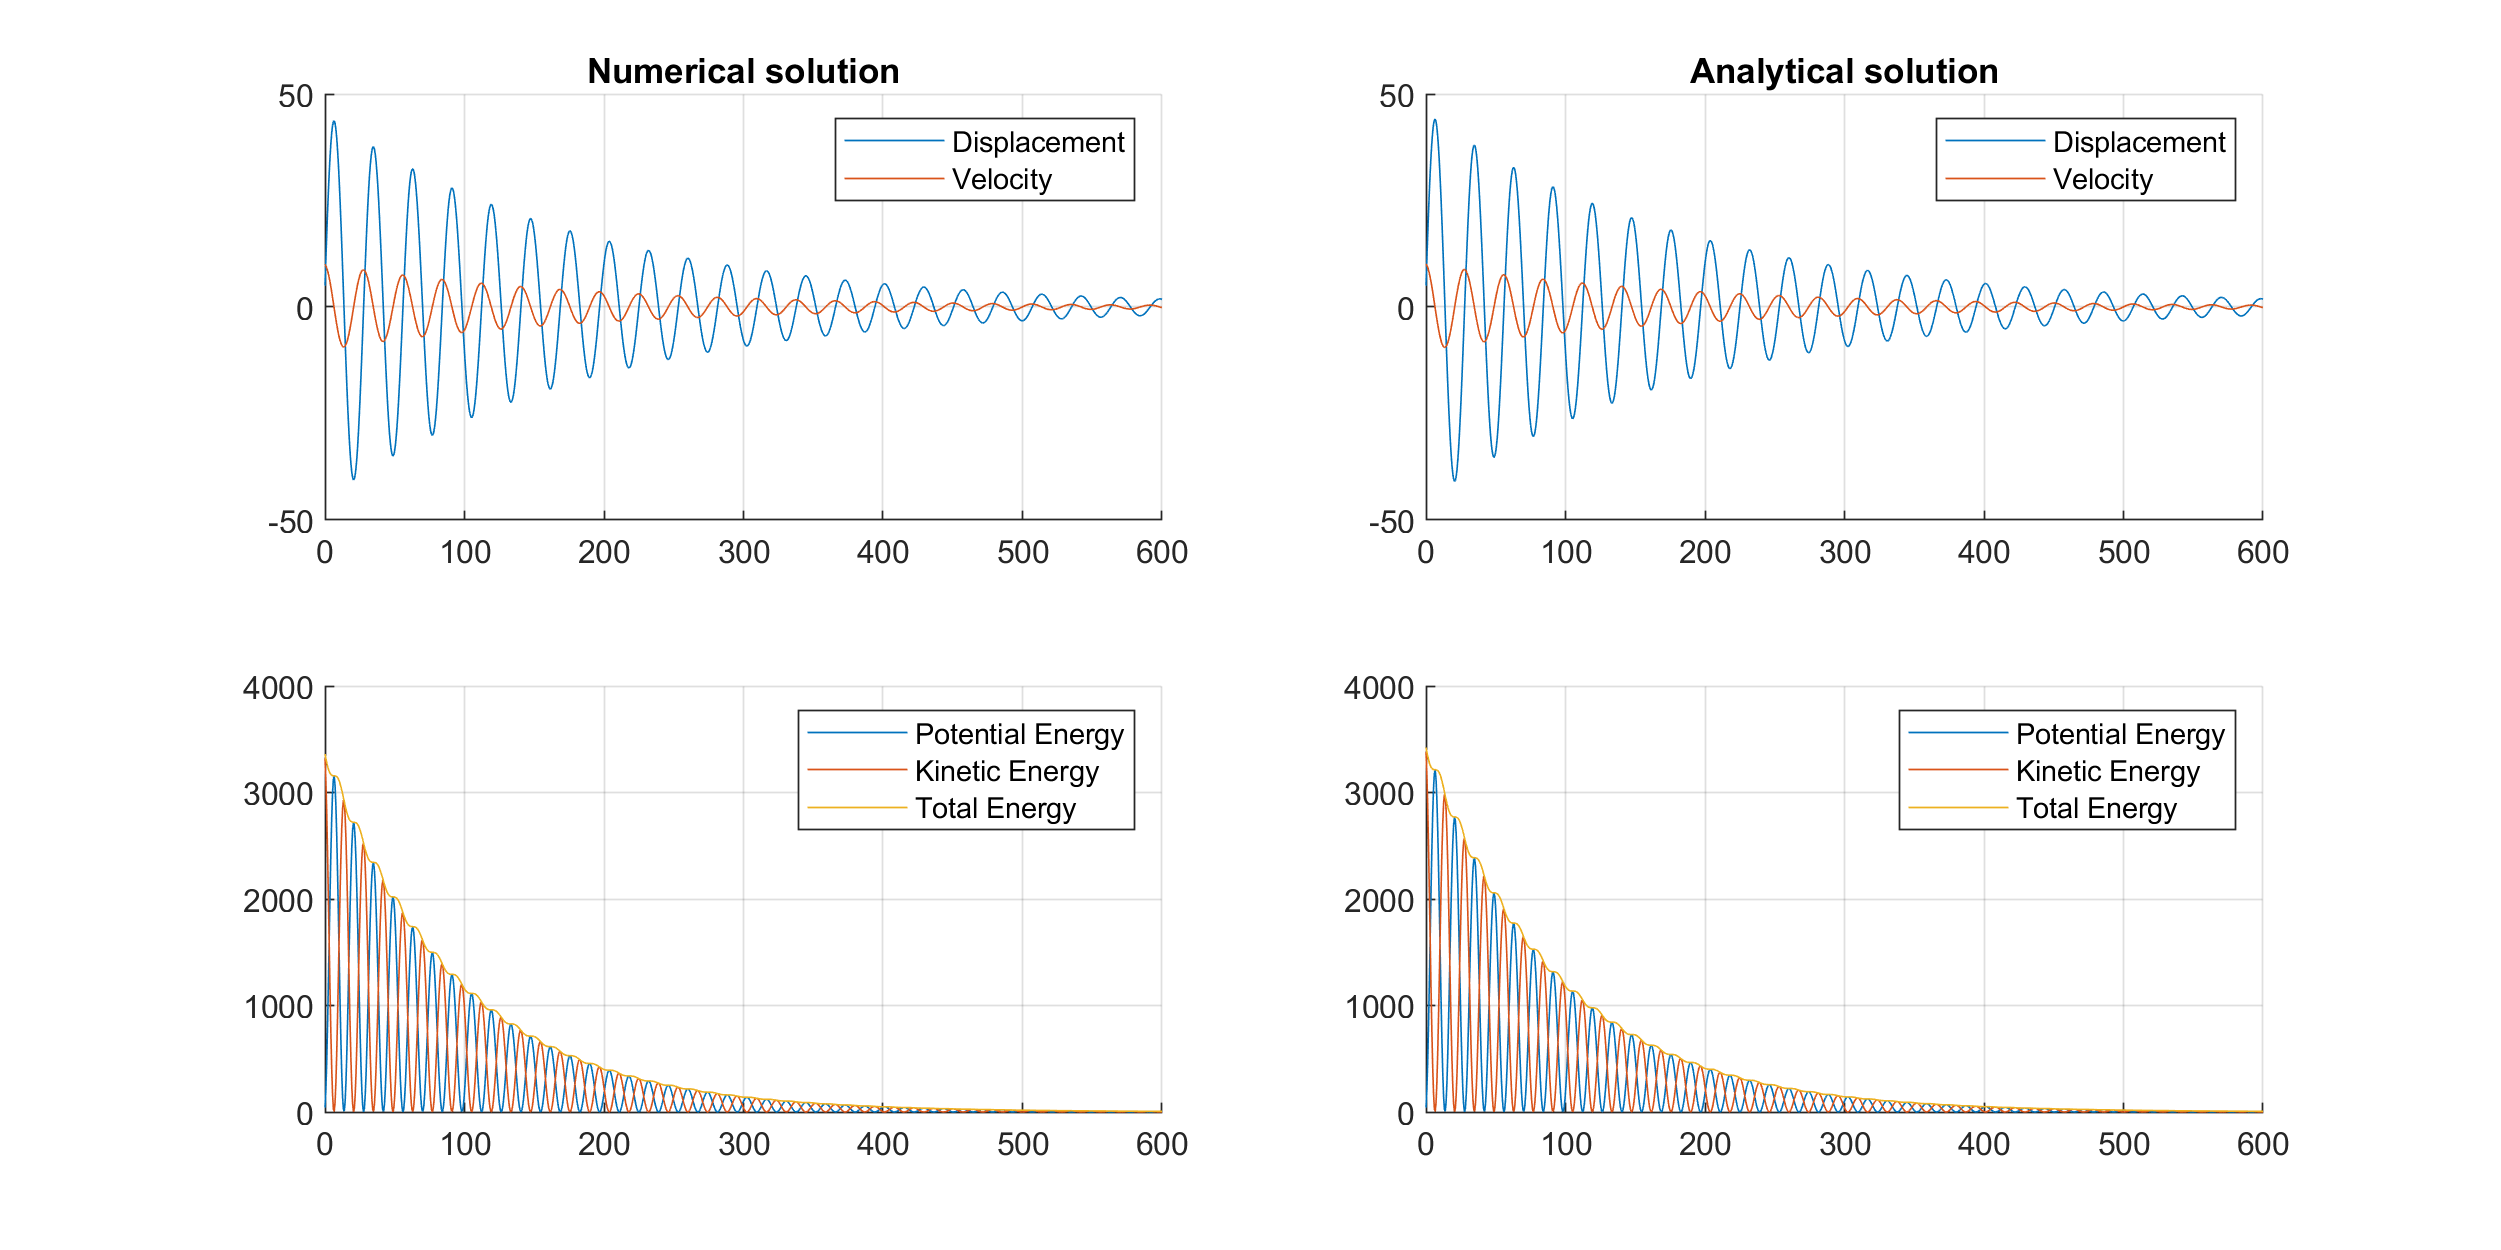

Elapsed time is 2.519454 seconds.


time = linspace(0.0, 600.0, 1000);
compare_q(m, k, c, x0, v0, f, time);

        In the case of an underdamped oscillator, the differences can hardly be seen at all. From what we've deduced earlier, the errors accumulate over time, so that's when they should be visible. The problem here is that damping will result in the oscillator reaching the equilibrium point at some point, meaning that the object stopped moving and there's no more energy within the system. In this case, the oscillator got to that point relatively quickly, so we can't notice any change between the plots. In order to make this point clearer, let's see what happens when the damping ratio is much smaller.

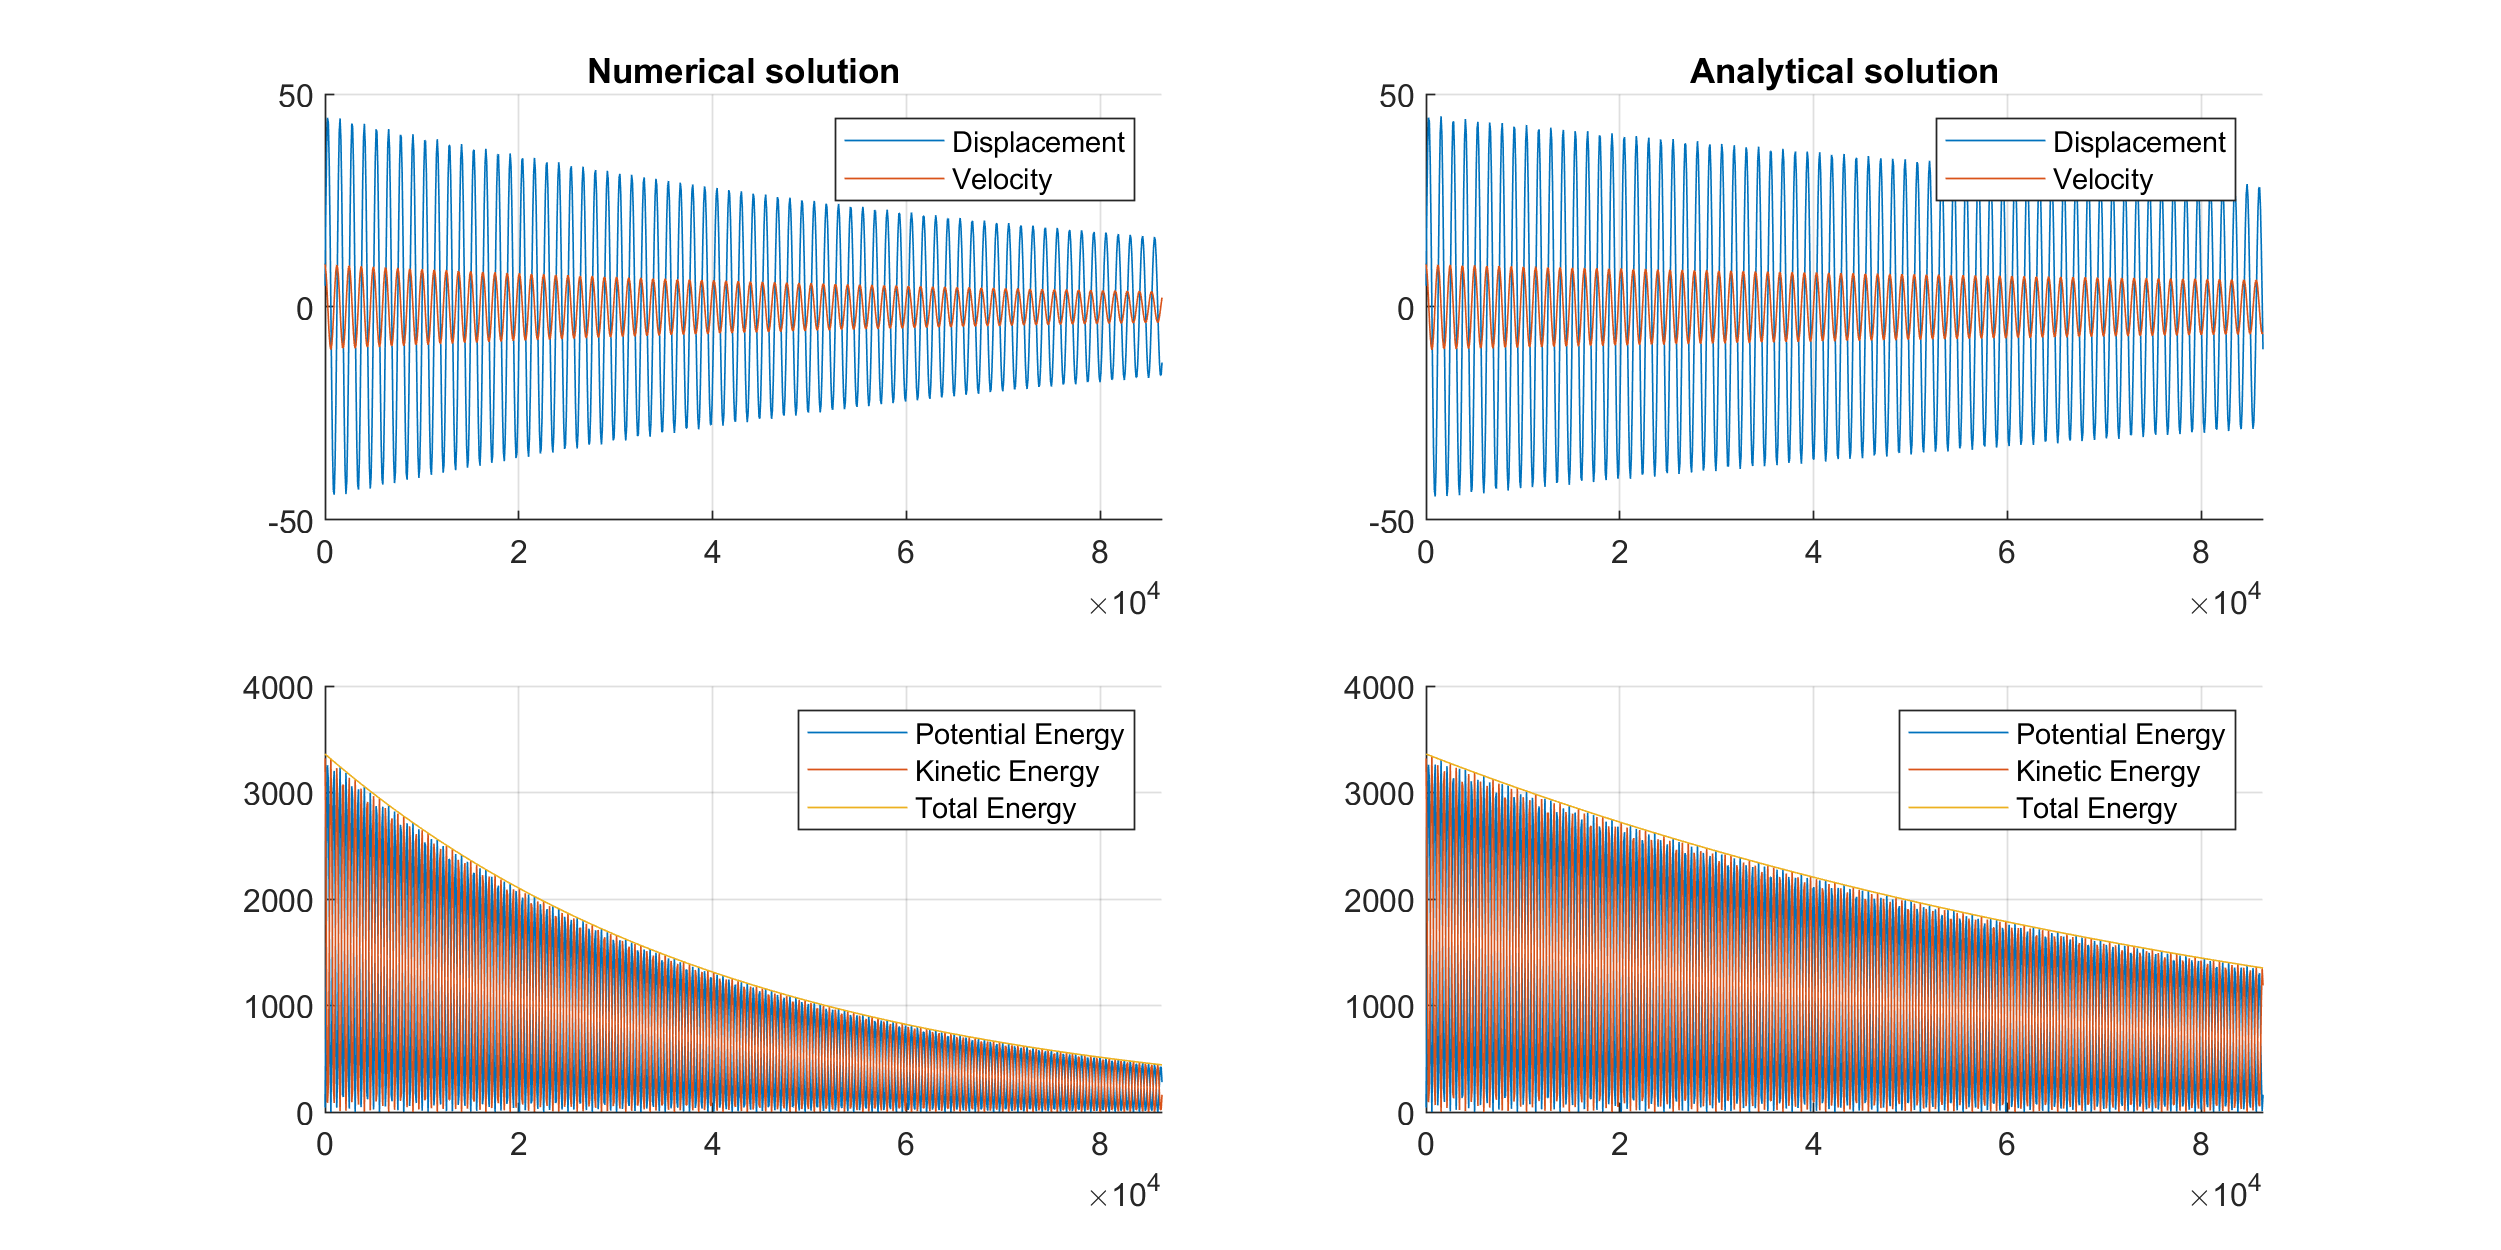

Elapsed time is 1.959640 seconds.


c = 0.0007;
time = linspace(0.0, 86400.0, 1000);
compare_q(m, k, c, x0, v0, f, time);

        Here we can observe somewhat similar results to the oscillator without damping on the right side, the analytical method. The numerical method is also similar but decreases at a faster rate due to the aforementioned reasons above. We can therefore conclude that the numerical solution behaves as if there was a hidden damping coefficient that is added to the real one. But in order to be sure, let's see what would happen with a model that wasn't underdamped.

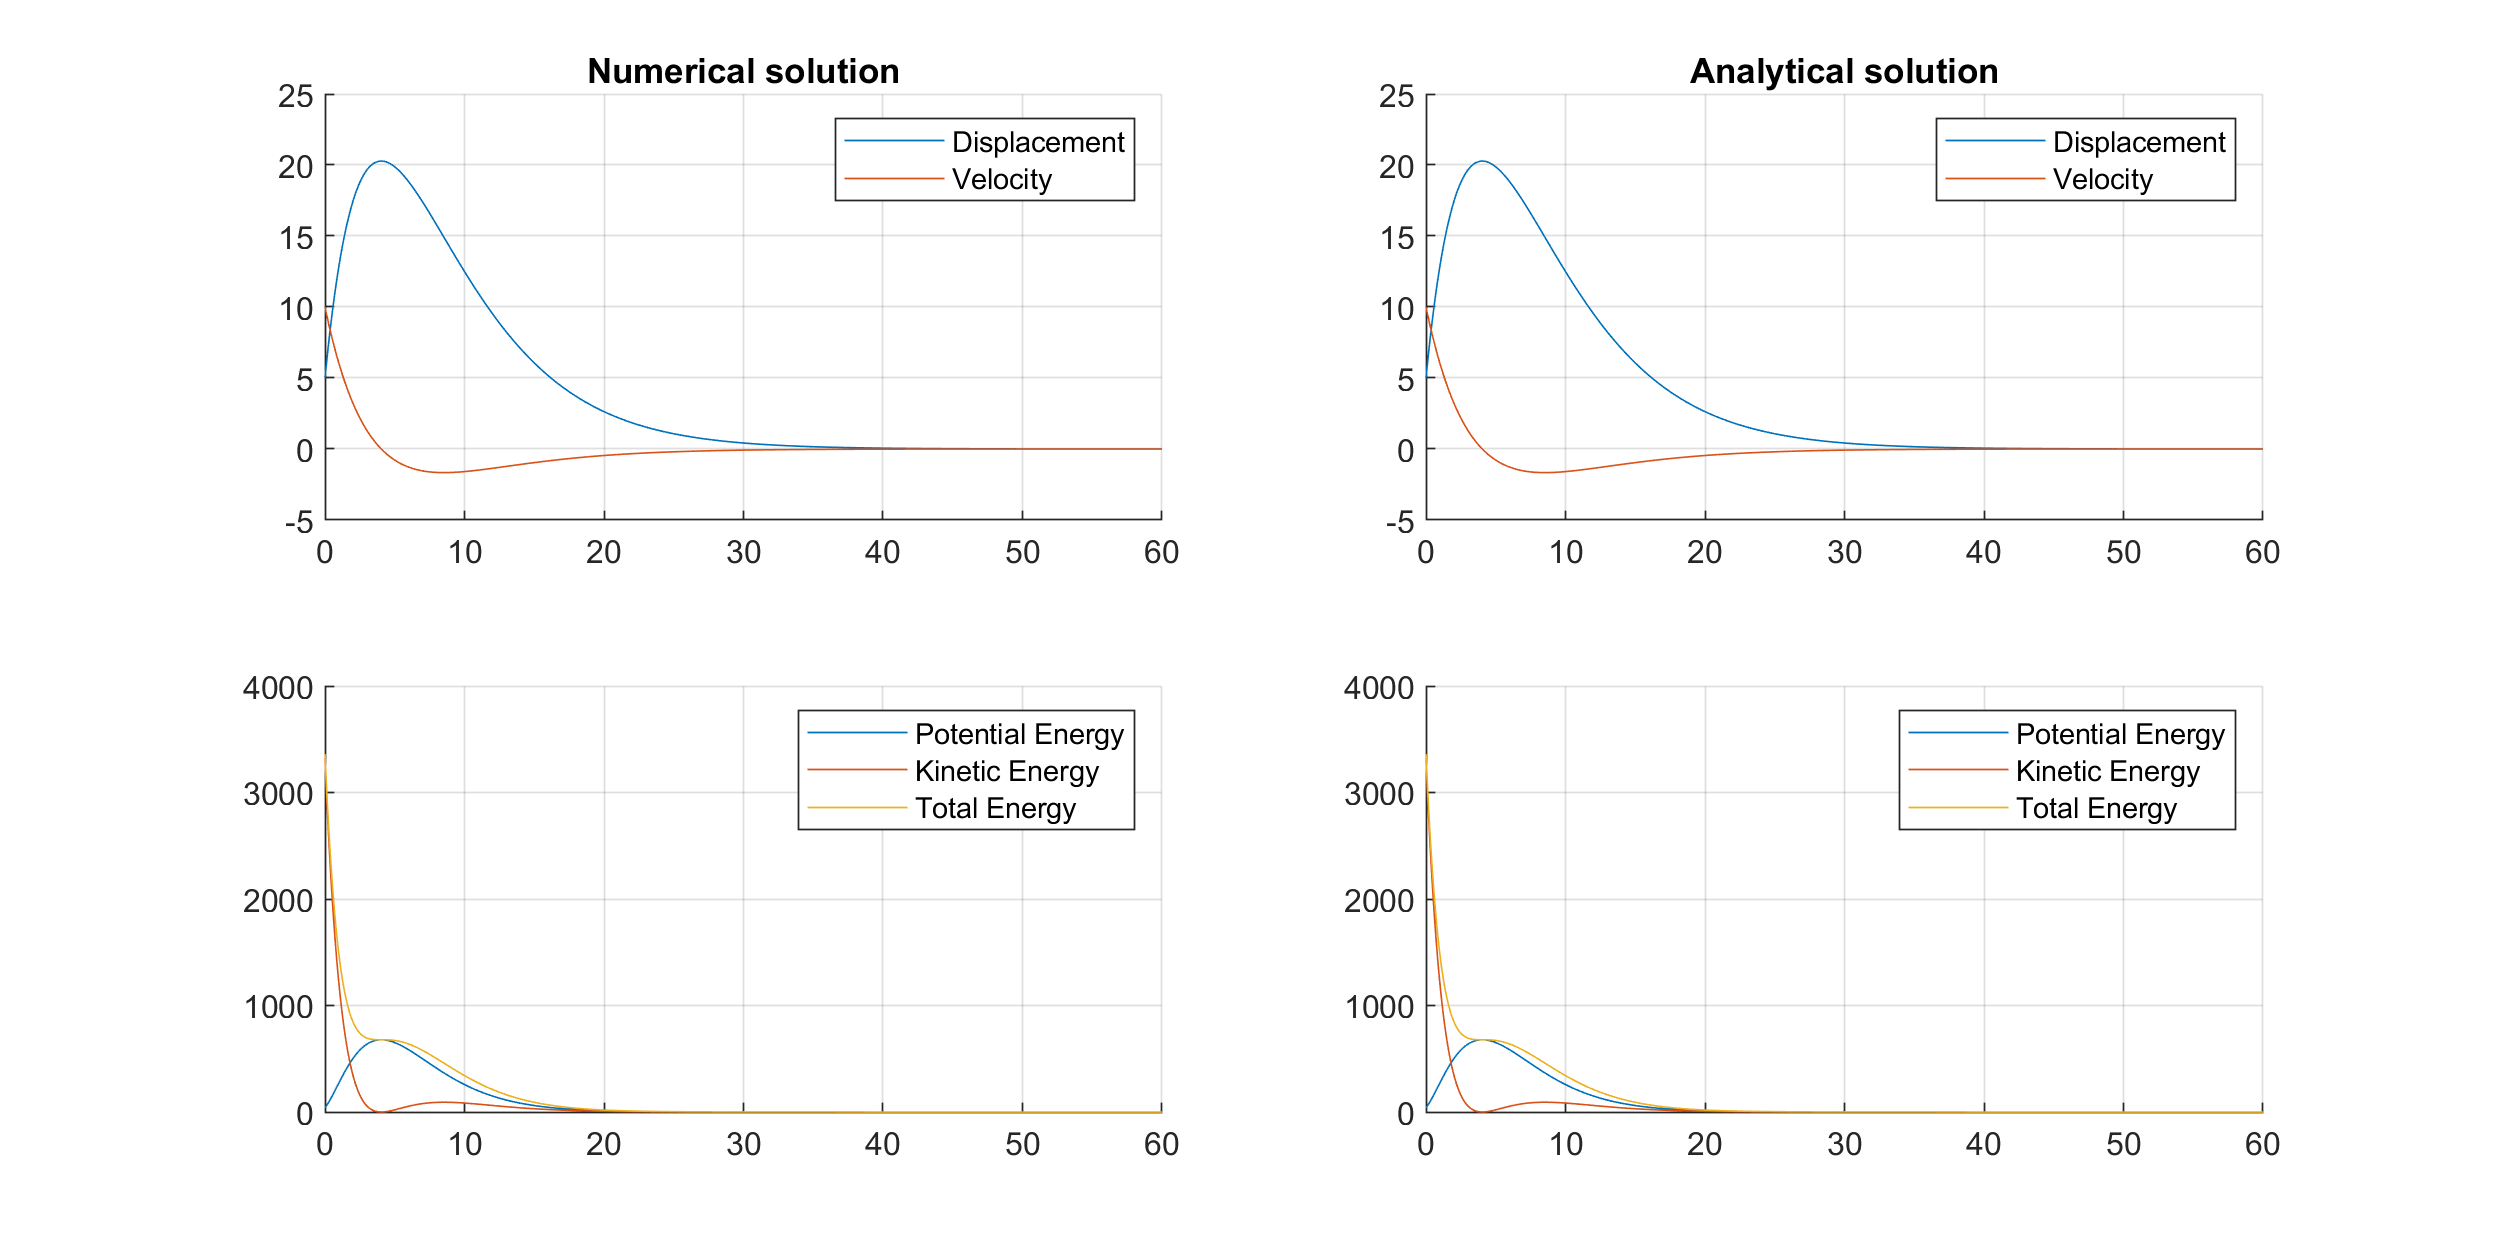

Elapsed time is 1.402375 seconds.


c = 2*sqrt(k*m);
time = linspace(0.0, 60.0, 1000);
compare_q(m, k, c, x0, v0, f, time);

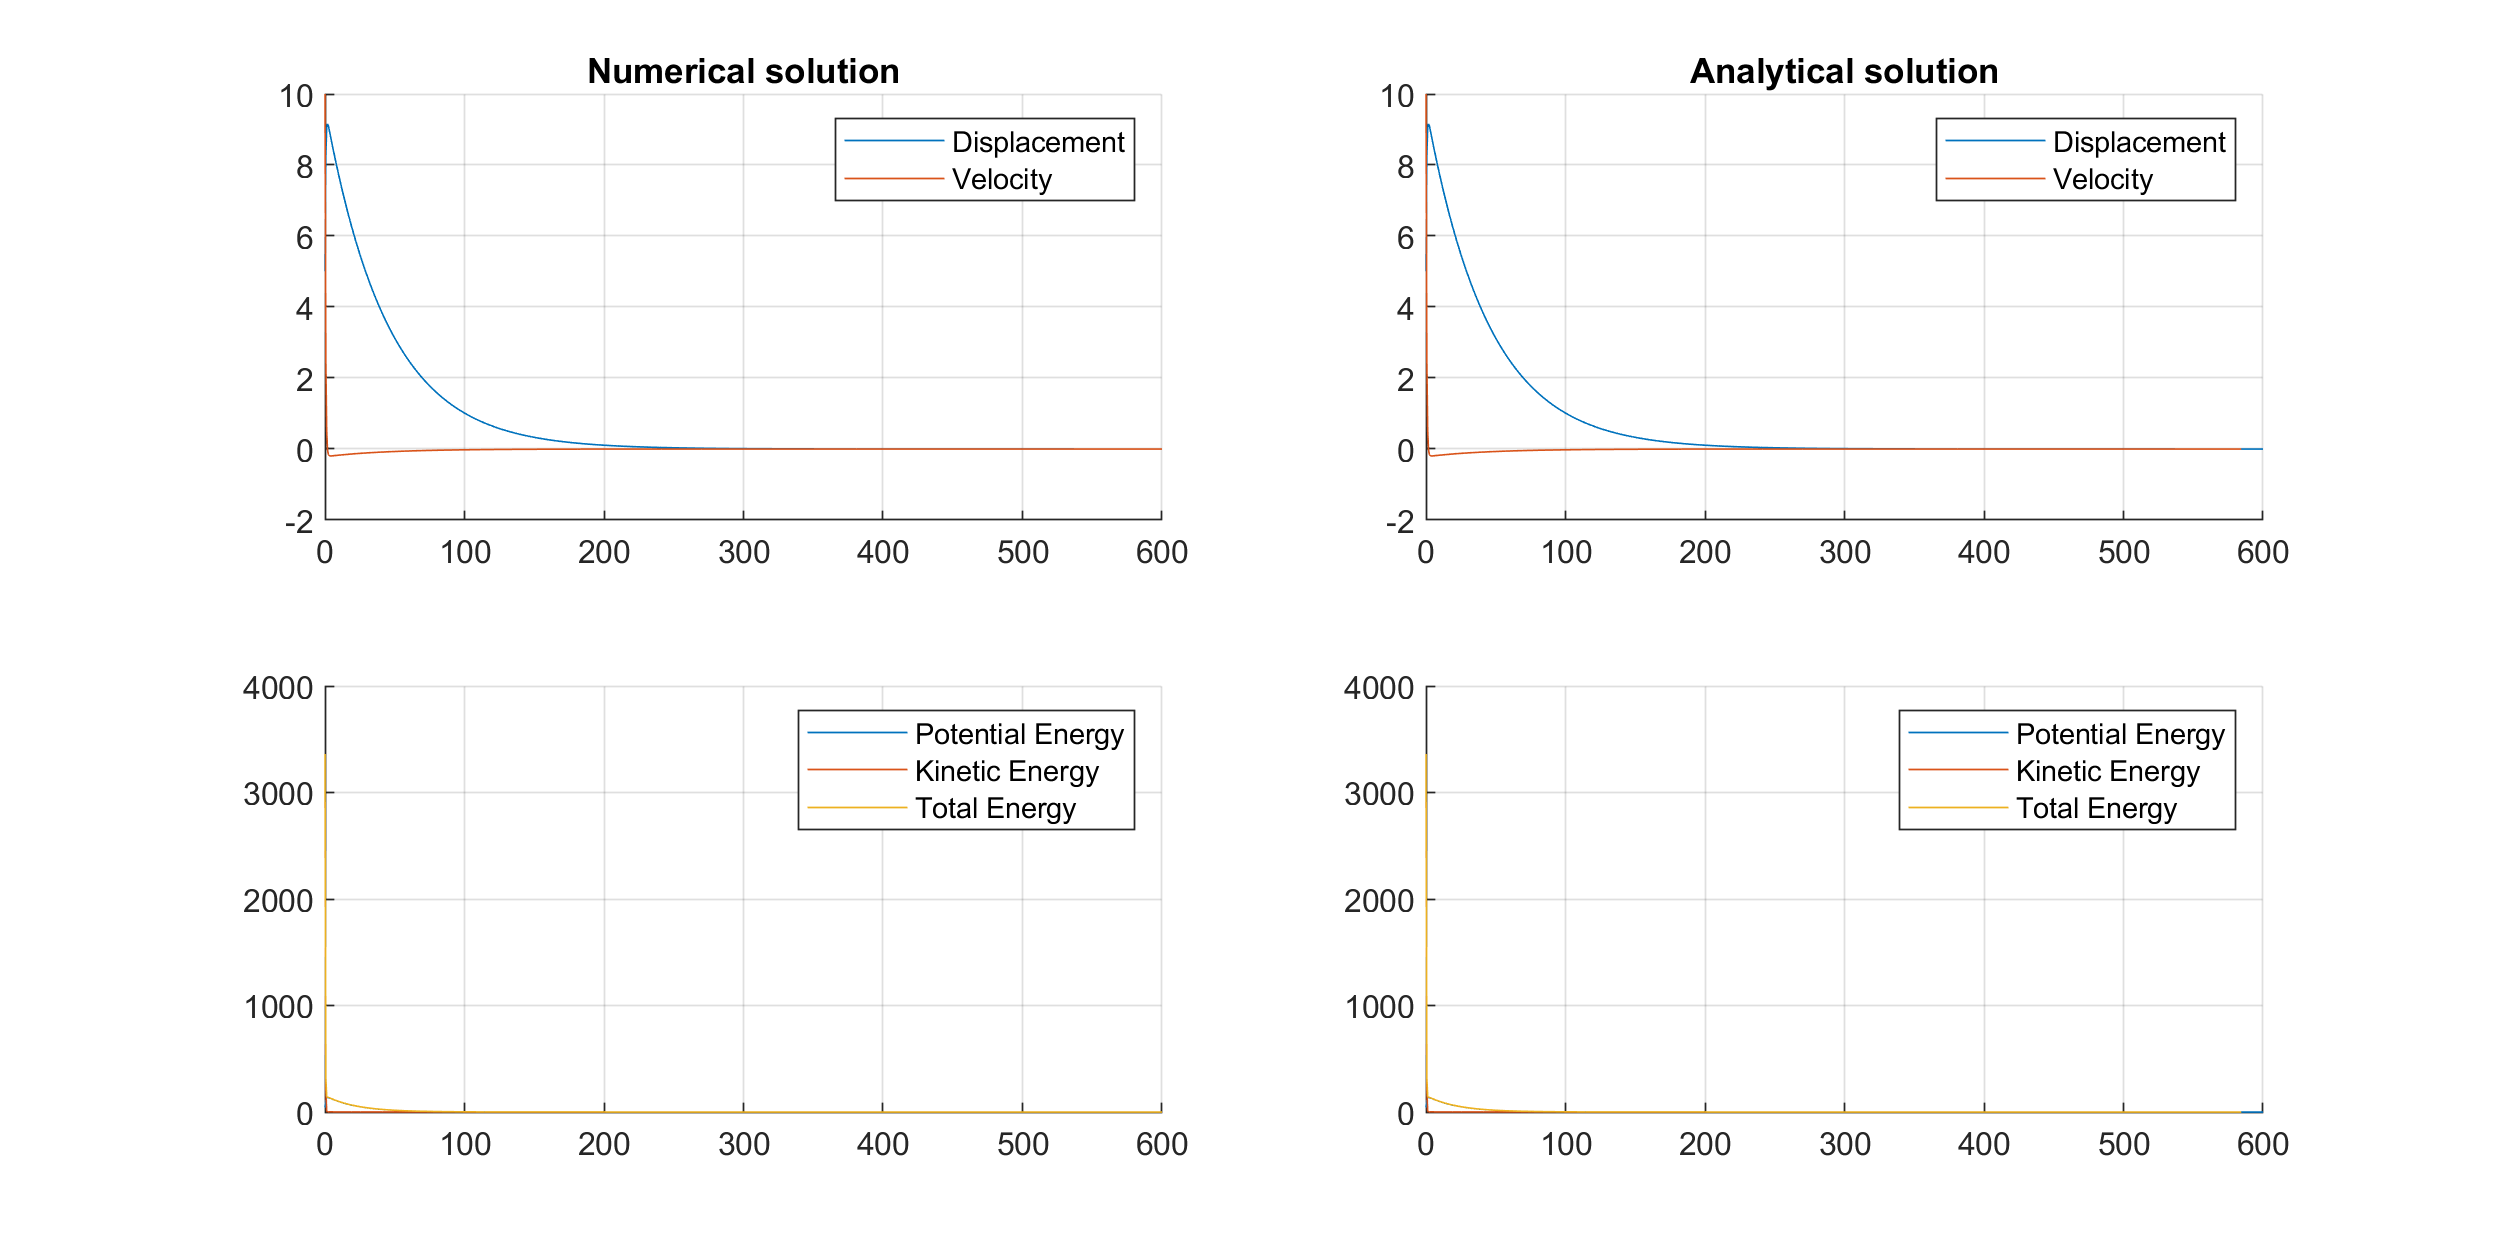

Elapsed time is 2.489564 seconds.


c = 10*sqrt(k*m);
time = linspace(0.0, 600.0, 1000);
compare_q(m, k, c, x0, v0, f, time);

        The truth is that in both the critically damped and overdamped cases the numerical and analytical solutions will be the same. This is because in both cases the system will never oscillate. In other words, it's simply a decay to the equilibrium point. Obviously, the values aren't identical due to the nature of the methods, but for practical uses they are the same whenever the damping ratio is greater than or equal to 1.

        Lastly, something interesting happens when an external driving force is added into the mix. In order to see it, we will ignore damping for now.

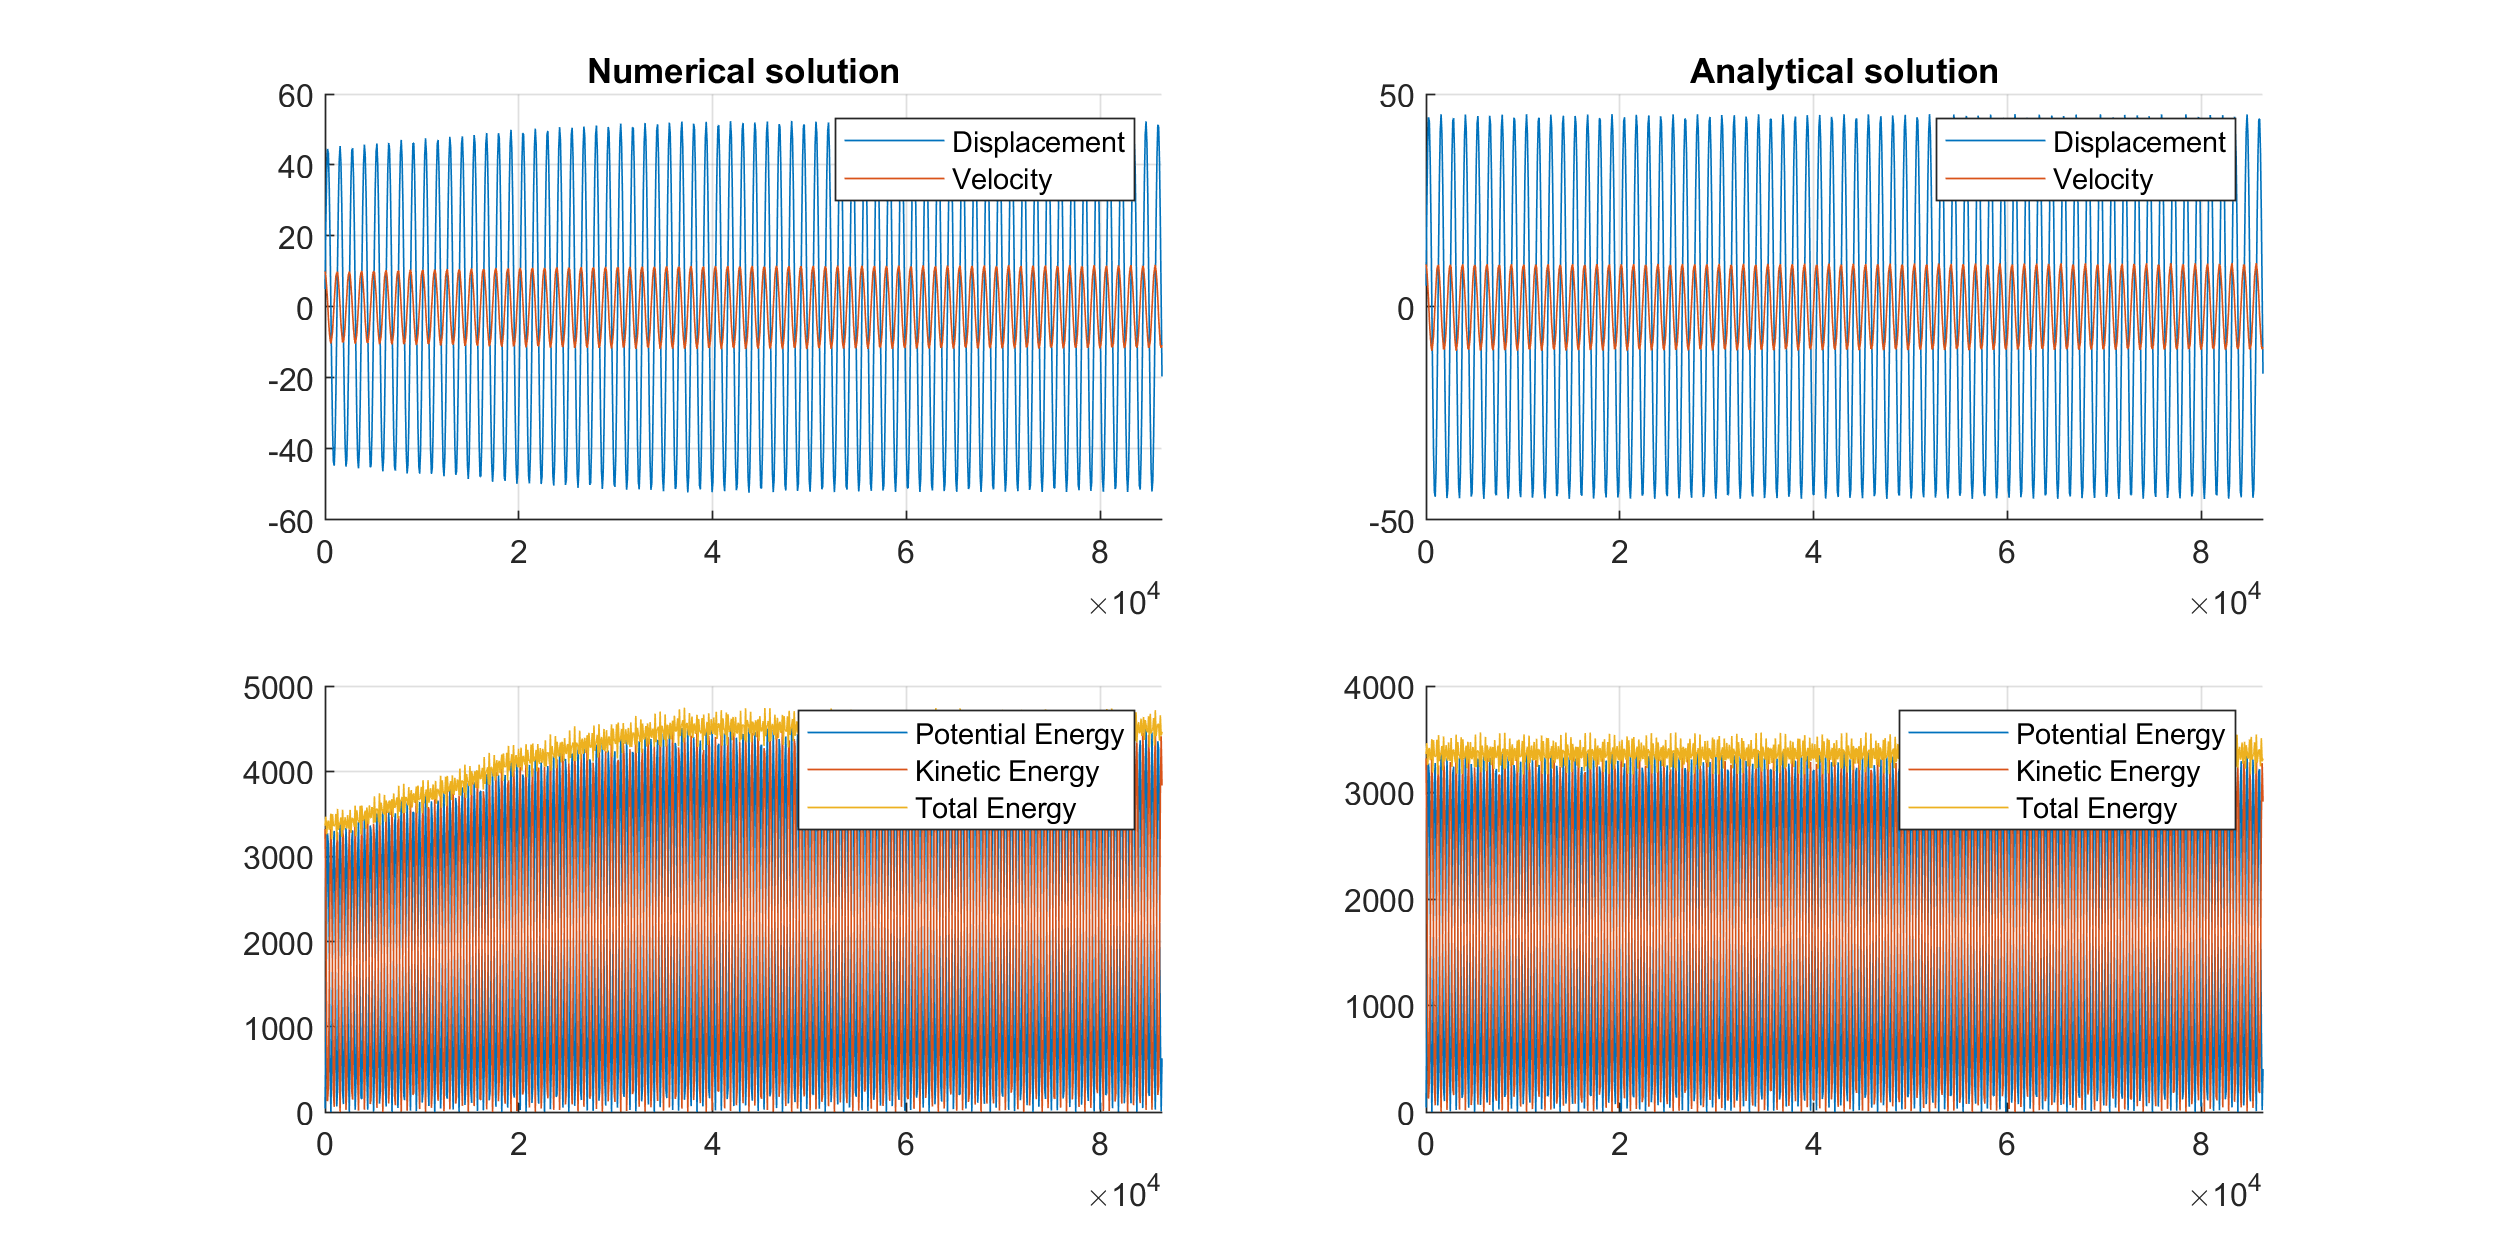

Elapsed time is 6.691792 seconds.


c = 0.0;
f = @(t) 50*cos(2.5*t);
time = linspace(0.0, 86400.0, 1000);
compare_q(m, k, c, x0, v0, f, time);

        Using the same simple harmonic oscillator at the start but with a driving force shows us some interesting findings. Firstly, the total energy in the analytical solution is no longer constant but now dependent on the driving force. In our case, that force is periodic, therefore the total energy will also fluctuate periodically. Secondly, the numerical solution behaves weirdly in this case. It starts off the same as the analytical one, which is to be expected, but then instead of losing energy due to energy drift we see that it's actually gaining energy up until a certain point where, for some reason, it stops increasing further. Furthermore, the total energy in both cases seems to oscillate in the same manner since we're using the same external force. In the end, it would make sense to generate energy in a situation like this because the system isn't closed anymore, but I cannot explain why the numerical method acts like this, though it's fair to say that the result's completely wrong.

        Lastly, let's check one final example with both damping and a driving force affecting the system.

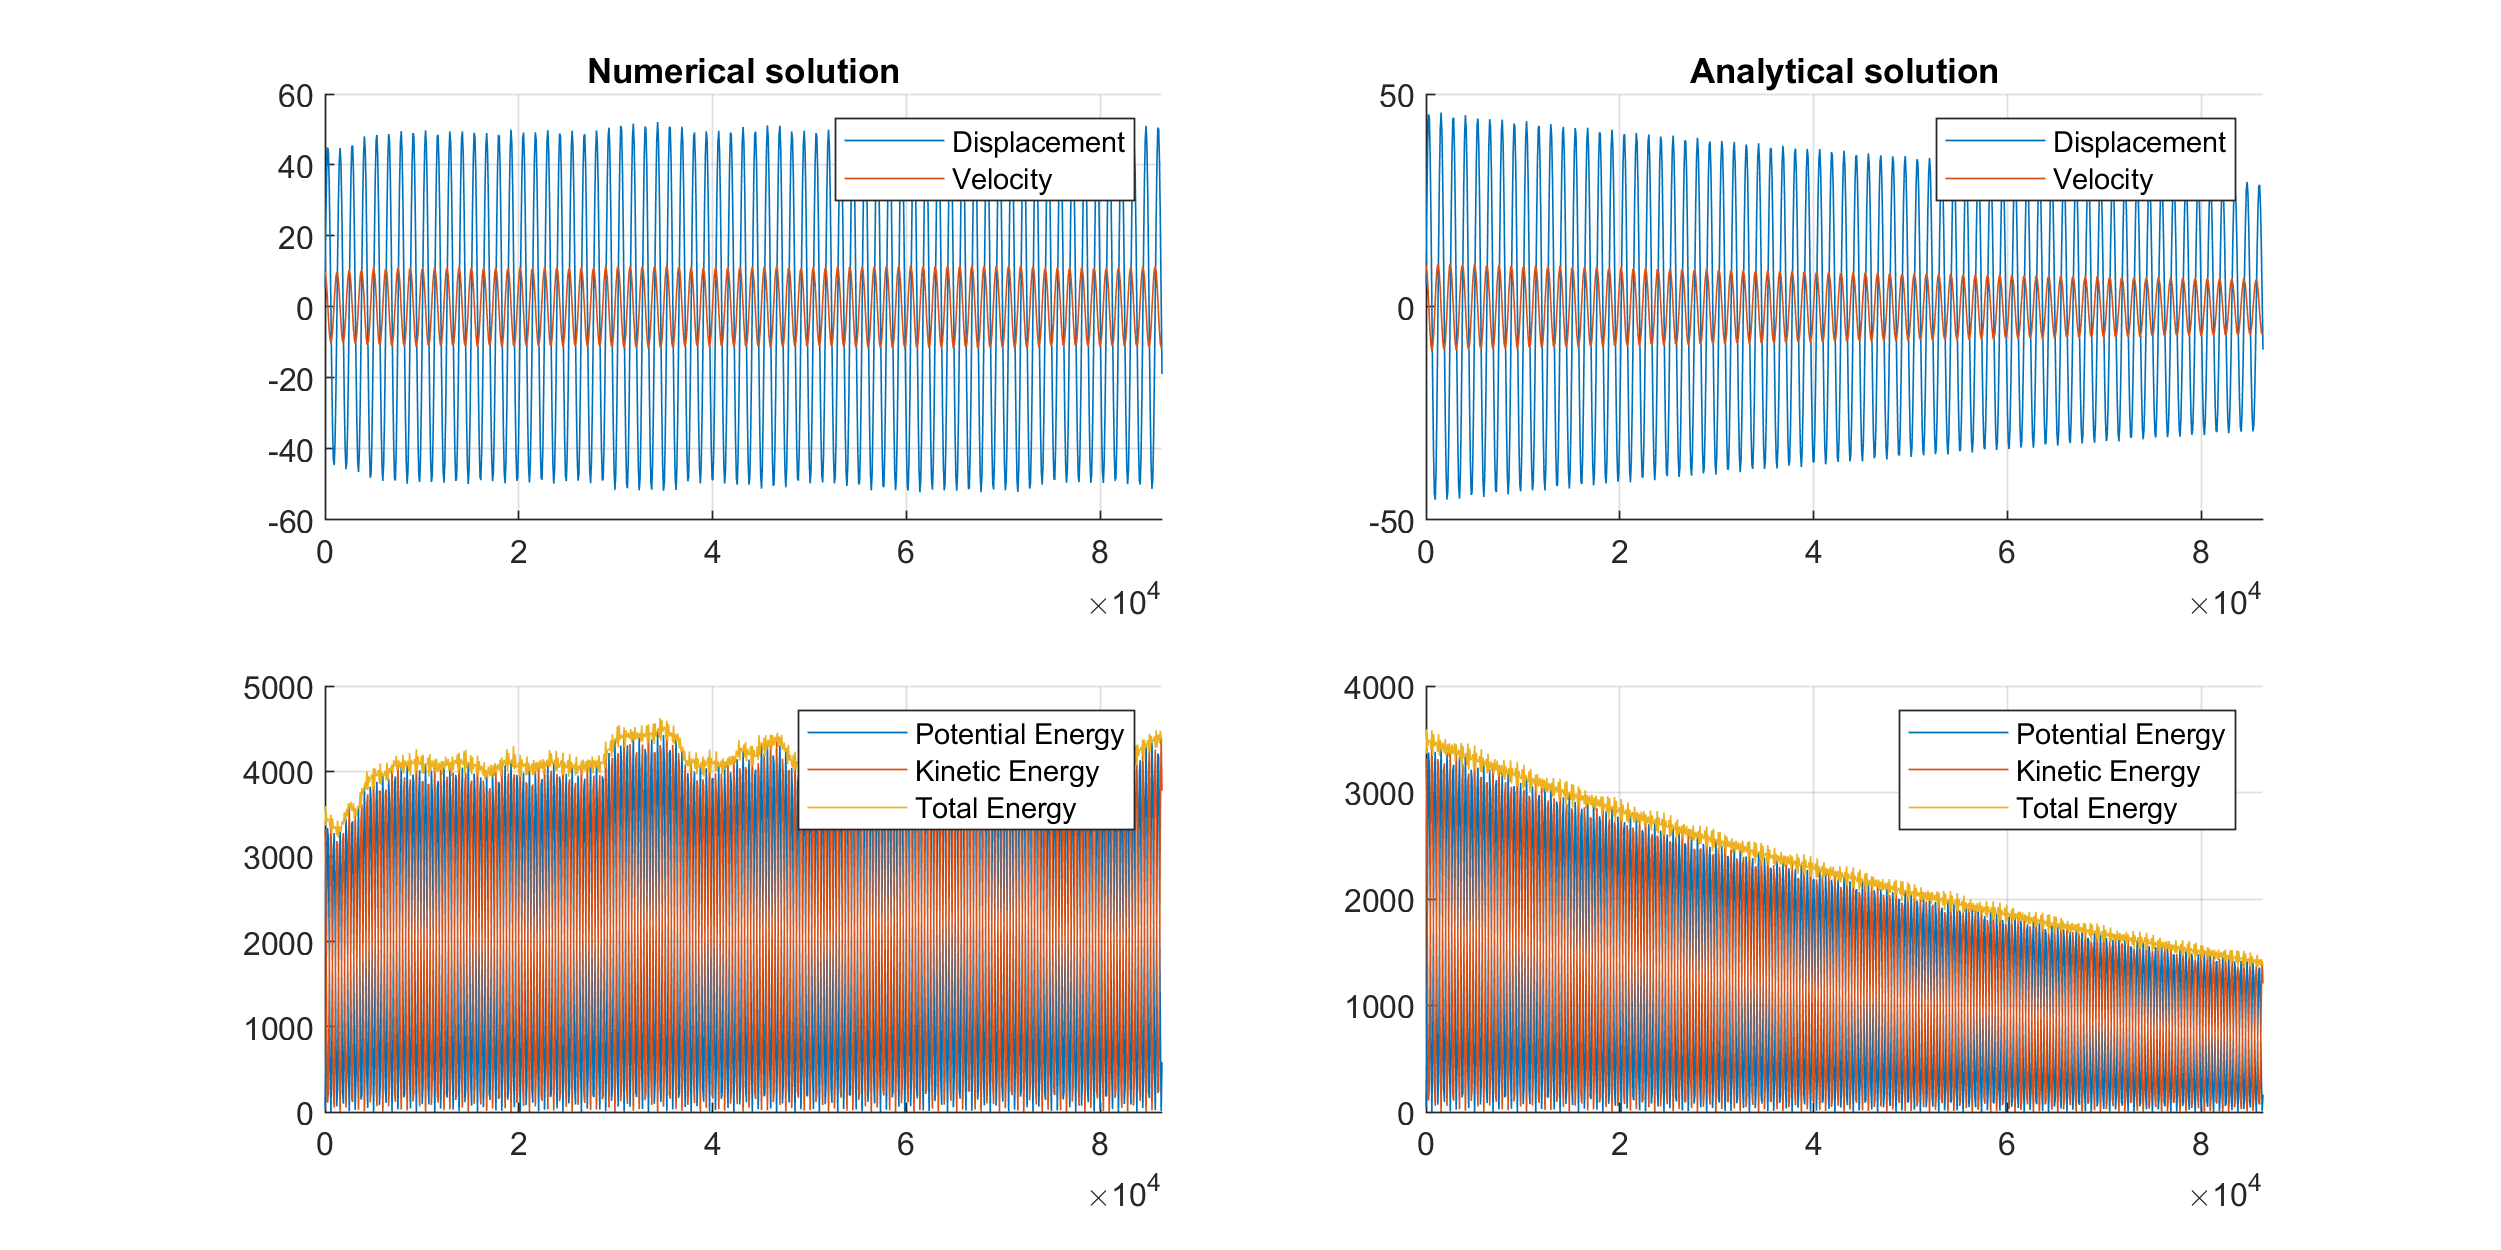

Elapsed time is 6.564052 seconds.


c = 0.0007;
f = @(t) 35*sin(2.72*t);
time = linspace(0.0, 86400.0, 1000);
compare_q(m, k, c, x0, v0, f, time);

        We notice that a damped and driven harmonic oscillator acts like one would expect: a combination of both being damped and driven at the same time. It's interesting to note how chaotic the numerical solution becomes over time. In a way, both the numerical one and the analytical one adhere to their own patterns from the plots above, where the analytical solution behaves as expected and the numerical solution is either losing energy when it shouldn't or gaining energy at random times for no good reason. The computation time is also much longer whenever a driving force is included in comparison to when it's not due to the time it takes to calculate the integrals around it.

## `Concluding the report`

        In conclusion, we've noticed many interesting results within this report. I've managed to find the analytical equation of any harmonic oscillator, be it simple, damped or driven and compared how well it behaves compared to the easier to implement Runge-Kutta method. The differences were interesting and highlighted the downsides of the numerical approach of solving differential equations. Despite all the downsides, the numerical approximations are still widely used in the field for mostly 2 reasons alone: they are simpler to work with and the results are accurate within a short timeframe. Sometimes, that's all one needs in order to complete their goals, which is why they are still useful. On top of that, some problems can't even be approached analytically, meaning that numerical algorithms are the only way to get an answer. However, one must be very cautious of the dangers of such methods to ensure the best possible results. In the end, it's all about using the right tool for the right job.